clear;
close all;     
format shortG;

### **Function of Risk Measures and VAR and CVAR at 95%, 97% and 99%**

% Calculates risk statistics and Value at Risk (VaR) for a single asset.
function RiskStats = calculateRiskStats(LogReturns, AssetName)
    LogReturns = LogReturns(~isnan(LogReturns));  
    nReturns = length(LogReturns);

    % Statistic in decimals
    mean_ret = mean(LogReturns);       
    std_dev = std(LogReturns);         
    variance = var(LogReturns);        
    skew_val = skewness(LogReturns);         
    kurt_val = kurtosis(LogReturns);         

    RiskStats = table({AssetName}, nReturns, mean_ret*100, std_dev*100, variance*100, kurt_val, skew_val, ...
                      'VariableNames', {'Asset Name', 'Number_of_Returns', 'Mean (%)', 'StdDev (%)', ...
                                        'Variance (%)', 'Kurtosis', 'Skewness'});

    confidence_levels = [0.95, 0.97, 0.99];

    for j = 1:length(confidence_levels)
        z = norminv(confidence_levels(j)); 
        VaR = -(mean_ret + z * std_dev);
        phi_z = exp(-0.5 * z^2) / sqrt(2*pi);
        CVaR = -(mean_ret + std_dev * (phi_z / (1 - confidence_levels(j))));

        RiskStats{1, ['VaR_' num2str(round(confidence_levels(j)*100))]} = VaR * 100;
        RiskStats{1, ['CVaR_' num2str(round(confidence_levels(j)*100))]} = CVaR * 100;
    end

    RiskStats{:, 2:end} = round(RiskStats{:, 2:end}, 4);    
    disp(RiskStats);
end


### Histogram with density curve and Q-Q plot

% This function generates a histogram with density curve and a Q-Q plot for a single asset.
function generatePlotsForAsset(LogReturns, AssetName)   
    % Histogram Plot
    figHist = figure;
    histogram(LogReturns, 30, 'Normalization', 'pdf'); 
    hold on;
    [f, xi] = ksdensity(LogReturns); 
    plot(xi, f, 'LineWidth', 2, 'Color', 'r'); 
    hold off;
    title(['Histogram and Density Curve of Log Returns for ', AssetName]);
    xlabel('Log Returns');
    ylabel('Density');
    
    % Q-Q Plot
    figQQ = figure;
    qqplot(LogReturns);
    title(['Q-Q Plot of Log Returns for ', AssetName]);  
end



### Function of iid Proprierties Test (Autocorrelation and Normality) - (Ljung-Box and D'Agostino-Pearson)

% IID PROPERTIES TEST (Autocorrelation and Normality) - (LJUNG-BOX and D'AGOSTINO-PEARSON)
% Checks whether there are significant autocorrelations at any lag, which would indicate that the data is not independent.
% Tests whether the data follows a normal distribution and checks for skewness and kurtosis.
function [autocorrResults, turningPointResults] = testIIDProperties(LogReturns, AssetName)
    autocorrResults = table('Size', [1, 8], 'VariableTypes', {'double', 'double', 'double', 'double', 'double', 'cell', 'cell', 'cell'}, ...
        'VariableNames', {'LjungBox_pValue', 'LjungBox_QStat', 'LjungBox_CritVal', 'Normality_pValue', 'JarqueBera_pValue', ...
                          'AutocorrelationConclusion', 'NormalityConclusion_JB', 'NormalityConclusion_DA'}, ...
        'RowNames', {AssetName});

    % Ljung-Box test for autocorrelations
    [~, pVal, QStat, critVal] = lbqtest(LogReturns, 'Lags', 10);
    autocorrResults{1, 'LjungBox_pValue'} = pVal;
    autocorrResults{1, 'LjungBox_QStat'} = QStat;
    autocorrResults{1, 'LjungBox_CritVal'} = critVal;
    if pVal < 0.05
        autocorrConclusion = 'Autocorrelated';  
    else
        autocorrConclusion = 'No-Autocorrelated';  
    end
    
    % Jarque-Bera test for normality
    [~, pJB] = jbtest(LogReturns);
    autocorrResults{1, 'JarqueBera_pValue'} = pJB;
    if pJB < 0.05
        normalityConclusionJB = 'Not Normal';  
    else
        normalityConclusionJB = 'Normal';  
    end
    
    % D’Agostino-Pearson test for normality
    n = length(LogReturns);
    skewVal = skewness(LogReturns);
    kurtVal = kurtosis(LogReturns);
    SES = sqrt(6 * n * (n - 1) / ((n - 2) * (n + 1) * (n + 3)));
    ZS = skewVal / SES;
    SEK = 2 * SES * sqrt((n^2 - 1) / ((n - 3) * (n + 5)));
    ZK = (kurtVal - 3) / SEK;
    K2 = ZS^2 + ZK^2;

    pValueDA = 1 - chi2cdf(K2, 2);
    autocorrResults{1, 'Normality_pValue'} = pValueDA;
    if pValueDA < 0.05
        normalityConclusionDA = 'Not Normal';  
    else
        normalityConclusionDA = 'Normal';  
    end
    autocorrResults{1, 'AutocorrelationConclusion'} = {autocorrConclusion};
    autocorrResults{1, 'NormalityConclusion_JB'} = {normalityConclusionJB};
    autocorrResults{1, 'NormalityConclusion_DA'} = {normalityConclusionDA};
    
    % Turning Point Test for iid
    % For the Turning Point test, we calculate the number of turning points in the data, the expected number of turning points,
    % the z-score, and the p-value for the test.
    turningPointResults = table('Size', [1, 6], 'VariableTypes', {'double', 'double', 'double', 'double', 'logical', 'cell'}, ...
        'VariableNames', {'TurningPoints', 'ExpectedTurningPoints', 'ZScoreTurningPoints', 'PValueTurningPoints', 'IsIID', 'IIDConclusion'}, ...
        'RowNames', {AssetName});

    % Calculate turning points
    diffData = diff(LogReturns);
    turningPoints = sum(diffData(1:end-1) .* diffData(2:end) < 0);  
    expectedTurningPoints = (n - 1) / 2;  
    varianceTurningPoints = (16 * n - 29) / 90;  
    zScore = (turningPoints - expectedTurningPoints) / sqrt(varianceTurningPoints);  
    pValue = 2 * (1 - normcdf(abs(zScore)));  
    if pValue < 0.05
        Turning_points_Conclusion = 'Not iid';  
    else
        Turning_points_Conclusion = 'iid';  
    end
    
    % Add the results to the table
    turningPointResults{1, 'TurningPoints'} = turningPoints;
    turningPointResults{1, 'ExpectedTurningPoints'} = expectedTurningPoints;
    turningPointResults{1, 'ZScoreTurningPoints'} = zScore;
    turningPointResults{1, 'PValueTurningPoints'} = pValue;
    turningPointResults{1, 'IIDConclusion'} = {Turning_points_Conclusion}; 
    
    % Display the results
    disp(autocorrResults);
    disp(turningPointResults);
end



### Graphic ACF and PACF

function plotACFandPACF(LogReturns, AssetName, numLags)
    figure('Name', ['ACF & PACF for ', AssetName]);

    % ACF
    subplot(2,1,1);
    autocorr(LogReturns, 'NumLags', numLags);
    title(['ACF for ', AssetName], 'FontSize', 12);
    xlabel('Lag', 'FontSize', 10);
    ylabel('Autocorrelation', 'FontSize', 10);
    grid on;

    % PACF
    subplot(2,1,2);
    hold on;
    parcorr(LogReturns, 'NumLags', numLags);
    title(['PACF for ', AssetName], 'FontSize', 12);
    xlabel('Lag', 'FontSize', 10);
    ylabel('Partial Autocorrelation', 'FontSize', 10);
    grid on;
    sgtitle(['Model Identification (ACF & PACF) for ', AssetName], 'FontSize', 14, 'FontWeight', 'bold');
end


## **AR-GARCH **

***AR-GARCH (t-distribution)***

function [ADFResults, AR_GARCHResults, stdResiduals, ResidualDiagnostics, AdditionalDiagnostics, VaR_CVaR, EstModel, condVar] = AR_GARCH_Model_SingleAsset_tStudents(LogReturns, AssetName, ConfidenceLevels)
%% AR-GARCH (t-distribution) con VaR/CVaR coerenti

    if nargin < 3
        ConfidenceLevels = [0.95, 0.97, 0.99]; % default
    end

    %% 1. ADF Test for Stationarity
    [~, pValue, stat, ~, cValue] = adftest(LogReturns);
    if ~isempty(cValue) && numel(cValue) >= 2
        criticalVal = cValue(2);  % livello 5%
    else
        warning('ADF critical value not available, using default -2.86');
        criticalVal = -2.86;
    end
    stationarityConclusion = ternary(pValue < 0.05, "Stationary", "Non-Stationary");
    ADFResults = table(pValue, stat, criticalVal, stationarityConclusion, ...
        'VariableNames', {'pValue','TestStatistic','CriticalValue_5%','StationarityConclusion'}, ...
        'RowNames', {AssetName});

    %% 2. AR(1)-GARCH(1,1) Estimation with t-Distribution Innovations
    try
        varianceModel = garch(1,1);
        model = arima('Constant', NaN,'ARLags',1,'Variance',varianceModel,'Distribution','t');
        [EstModel, EstCov] = estimate(model, LogReturns, 'Display','off');
        [residuals, condVar] = infer(EstModel, LogReturns);
    catch ME
        warning(['AR-GARCH estimation failed for ', AssetName, '. Error: ', ME.message]);
        [ADFResults, AR_GARCHResults, stdResiduals, ResidualDiagnostics, AdditionalDiagnostics, VaR_CVaR, EstModel, condVar] = deal([]);
        return;
    end
    stdResiduals = residuals ./ sqrt(condVar);

    %% 3. Extract Model Parameters
    dof = EstModel.Distribution.DoF;
    params = [EstModel.AR{1}, EstModel.Variance.ARCH{1}, EstModel.Variance.GARCH{1}, ...
              EstModel.Variance.Constant, EstModel.Constant, dof];
    se = sqrt(diag(EstCov));
    persistence = params(2) + params(3);

    AR_GARCHResults = table({AssetName}, round(params(1),5), round(params(2),5), ...
        round(params(3),5), round(params(4),5), round(params(5),5), round(params(6),2), ...
        round(se(1),5), round(se(2),5), round(se(3),5), round(se(4),5), round(se(5),5), round(se(6),2), ...
        persistence, ...
        'VariableNames', {'AssetName','AR1','ARCH1','GARCH1','Omega','Constant','DoF', ...
                          'SE_AR1','SE_ARCH1','SE_GARCH1','SE_Omega','SE_Constant','SE_DoF','ARCHplusGARCH'});

    %% 4. Residual Diagnostics
    [~, lbq_p_resid] = lbqtest(stdResiduals,'Lags',10);
    [~, lbq_p_sqresid] = lbqtest(stdResiduals.^2,'Lags',10);
    tpResult = turnpointtest(stdResiduals);
    iidConclusion = ternary(tpResult.pValue<0.05,"non-i.i.d.","i.i.d.");

    ResidualDiagnostics = table(lbq_p_resid, lbq_p_sqresid, tpResult.pValue, iidConclusion, ...
        'VariableNames', {'LjungBox_Resids_pVal','LjungBox_ResidsSq_pVal','TurningPoint_pVal','iidConclusion'}, ...
        'RowNames',{AssetName});

    %% 5. Additional Diagnostics
    [~, pValueARCH, statARCH, critARCH] = archtest(stdResiduals,'Lags',5);
    [~, pValueJB, statJB] = jbtest(stdResiduals); % solo informativo
    AdditionalDiagnostics = table(pValueARCH, statARCH, critARCH, pValueJB, statJB, ...
        'VariableNames', {'ARCH_pValue','ARCH_TestStatistic','ARCH_CriticalValue_5%','JB_pValue','JB_TestStatistic'}, ...
        'RowNames',{AssetName});

    %% 6. VaR and CVaR coerenti con distribuzione t stimata
    n = length(LogReturns);
    sigma_t = sqrt(condVar); % volatilità condizionale
    nu = EstModel.Distribution.DoF;
    mu = EstModel.Constant;  % media AR-GARCH

    VaR_CVaR = table('Size',[1,length(ConfidenceLevels)*2],'VariableTypes',repmat("double",1,length(ConfidenceLevels)*2));
    varNames = cell(1,length(ConfidenceLevels)*2);

    for k = 1:length(ConfidenceLevels)
        cl = ConfidenceLevels(k);
        % VaR t-Student
        t_quant = tinv(cl, nu);
        VaR = -(mu + sigma_t(end)*t_quant*sqrt((nu-2)/nu));
        % CVaR t-Student (Expected Shortfall)
        pdf_t = @(x) tpdf(x,nu);
        ES = -(mu + sigma_t(end) * nu/(nu-1) * tpdf(t_quant,nu)/(1-cl));  

        VaR_CVaR{1,(k-1)*2+1} = VaR*100;       % VaR in percent
        VaR_CVaR{1,(k-1)*2+2} = ES*100;        % CVaR in percent
        varNames{(k-1)*2+1} = ['VaR_' num2str(round(cl*100))];
        varNames{(k-1)*2+2} = ['CVaR_' num2str(round(cl*100))];
    end
    VaR_CVaR.Properties.VariableNames = varNames;
    VaR_CVaR.Properties.RowNames = {AssetName};
end

%%  Helper functions
function result = turnpointtest(data)
    n = length(data);
    if n < 3, error("Data series must have at least 3 observations."); end
    tp = sum((data(2:end-1) > data(1:end-2) & data(2:end-1) > data(3:end)) | ...
             (data(2:end-1) < data(1:end-2) & data(2:end-1) < data(3:end)));
    expectedTP = 2*(n-2)/3;
    varianceTP = (16*n-29)/90;
    z = (tp-expectedTP)/sqrt(varianceTP);
    p = 2*(1-normcdf(abs(z)));
    result = struct('pValue',p,'TurningPoints',tp,'ExpectedTP',expectedTP);
end

function out = ternary(cond,valTrue,valFalse)
    if cond, out = valTrue; else, out = valFalse; end
end




### **Mean - Excess plot**

function plotMeanExcess(LogReturns, outputDir, AssetName, nPoints)
    if nargin < 4
        nPoints = 100; % default number of points
    end

    if ~exist(outputDir, 'dir')
        mkdir(outputDir);
    end

    % Creazione dei livelli di soglia
    u_values = linspace(min(LogReturns), max(LogReturns), nPoints);
    meanExcess = zeros(size(u_values));

    % Calcolo dell'eccedenza media
    for i = 1:length(u_values)
        u = u_values(i);
        exceedances = LogReturns(LogReturns > u);
        if ~isempty(exceedances)
            meanExcess(i) = mean(exceedances - u);
        else
            meanExcess(i) = NaN; % se non ci sono superamenti
        end
    end

    % Plot
    fig = figure('Visible','on');
    plot(u_values, meanExcess, 'LineWidth', 2);
    xlabel('Threshold u');
    ylabel('Mean Excess');
    title(['Mean Excess Plot - ' AssetName]);
    grid on;

    % Salvataggio
    saveas(fig, fullfile(outputDir, ['MeanExcess_' AssetName '.png']));
    disp(['Mean Excess plot salvato in: ' fullfile(outputDir, ['MeanExcess_' AssetName '.png'])]);
end


### Threshold selection

function threshold_selection(stdResiduals, AssetName, thresholds, p, outDir, leftTail)

    if nargin < 4, p = [0.99]; end
    if nargin < 5, outDir = pwd; end
    if nargin < 6, leftTail = false; end
    if ~exist(outDir, 'dir'), mkdir(outDir); end

    data = stdResiduals(:);
    data = data(~isnan(data));

    if leftTail
        data = -data; % invertiamo per modellare la coda sinistra
    end

    nU = numel(thresholds);
    nP = numel(p);
    meanExcess = nan(nU,1);
    VaR_est = nan(nU,nP);
    ES_est = nan(nU,nP);
    AD_stat = nan(nU,1);
    CVM_stat = nan(nU,1);

    for i = 1:nU
        u = prctile(data, thresholds(i));
        exceedances = data(data > u) - u; % sempre >0 dopo inversione
        
        if numel(exceedances) > 50
            % Mean Excess
            meanExcess(i) = mean(exceedances);

            % Fit GPD
            [parmhat,~] = gpfit(exceedances);
            xi = parmhat(1); sigma = parmhat(2);

            % VaR e ES per ciascun livello p
            for j = 1:nP
                q = 1 - (1-p(j)) * (length(data)/length(exceedances));
                arg = (q^(-xi))-1;
                if isreal(arg) && arg > -1e-8
                    VaR_est(i,j) = u + sigma/xi * arg;
                    if xi < 1
                        ES_est(i,j) = (VaR_est(i,j)+sigma-xi*u)/(1-xi);
                    else
                        ES_est(i,j) = NaN;
                    end
                else
                    VaR_est(i,j) = NaN;
                    ES_est(i,j) = NaN;
                end
            end

            % Goodness-of-Fit (manuale)
            [AD, CVM] = gpd_gof(exceedances, xi, sigma);
            AD_stat(i) = AD;
            CVM_stat(i) = CVM;
        end
    end

    % === 1. Mean Excess Plot ===
    fig1 = figure('Visible','off');
    plot(thresholds, meanExcess,'b-o','LineWidth',1.2);
    title(['Mean Excess Plot - ' AssetName]);
    xlabel('Quantile threshold (%)'); ylabel('Mean Excess');
    grid on;
    saveas(fig1, fullfile(outDir, [AssetName '_MEPlot.png']));
    close(fig1);

    % === 2. Stability Plot (VaR e ES) ===
    fig2 = figure('Visible','off');
    hold on;
    colors = lines(nP);
    for j = 1:nP
        plot(thresholds, VaR_est(:,j),'--','Color',colors(j,:),'LineWidth',1.2);
        plot(thresholds, ES_est(:,j),'-','Color',colors(j,:),'LineWidth',1.2);
    end
    title(['Stability Plot (VaR & ES) - ' AssetName]);
    xlabel('Quantile threshold (%)'); ylabel('Value');
    legendStrings = [strcat("VaR-",string(p)), strcat("ES-",string(p))];
    legend(legendStrings,'Location','best'); grid on;
    saveas(fig2, fullfile(outDir, [AssetName '_StabilityPlot.png']));
    close(fig2);

    % === 3. Goodness-of-Fit Plot ===
    fig3 = figure('Visible','off');
    plot(thresholds, AD_stat,'m-o','LineWidth',1.2); hold on;
    plot(thresholds, CVM_stat,'c-o','LineWidth',1.2);
    title(['Goodness-of-Fit - ' AssetName]);
    xlabel('Quantile threshold (%)'); ylabel('Statistic');
    legend('Anderson-Darling','CvM','Location','best'); grid on;
    saveas(fig3, fullfile(outDir, [AssetName '_GoF.png']));
    close(fig3);

    disp(['✅ Grafici salvati in: ' outDir]);
end

% === Funzione di supporto per GoF (AD e CvM) ===
function [AD_stat, CVM_stat] = gpd_gof(exceedances, xi, sigma)
    n = numel(exceedances);
    if n < 30
        AD_stat = NaN; CVM_stat = NaN; return;
    end
    
    % Trasforma i dati in U(0,1) usando la CDF della GPD
    U = cdf('GeneralizedPareto', exceedances, xi, sigma, 0);
    U = sort(U);

    % Cramér–von Mises
    i = (1:n)';
    CVM_stat = sum((U - (2*i-1)/(2*n)).^2) + 1/(12*n);

    % Anderson–Darling
    AD_stat = -n - mean((2*i-1).*(log(U) + log(1 - U(end:-1:1))));
end




## EVT 

**EVT with test to improve the affidability** - goodness-of-fit, bootstrap CI, rolling window, backtesting

function EVT_Results = EVT_POT_Model_Simplified(LogReturns, AssetName, thresholdLevels, opts)

    if nargin < 4, opts = struct(); end
    if ~isfield(opts,'leftTail'), opts.leftTail = false; end
    if ~isfield(opts,'gofSimulations'), opts.gofSimulations = 1000; end

    N = numel(LogReturns);
    OutTable = table();

    % Se modello perdite, inverti il segno (operiamo sempre sul "right tail")
    if opts.leftTail
        dataForEVT = -LogReturns(:);
    else
        dataForEVT = LogReturns(:);
    end

    for i = 1:numel(thresholdLevels)
        q = thresholdLevels(i);
        % Threshold (quantile)
        u = quantile(dataForEVT, q);
        exceedances = dataForEVT(dataForEVT > u) - u; 
        Nu = numel(exceedances);

        if Nu < 10
            warning('Superamenti troppo pochi per q = %.2f - %s (Nu=%d).', q, AssetName, Nu);
        end

        % Stima GPD
        xi = NaN; sigma = NaN;
        try
            ph = gpfit(exceedances);
            xi = ph(1); sigma = ph(2);
        catch
            warning('Errore GPD per q = %.2f', q);
        end

        % VaR e CVaR
        if ~isnan(xi)
            p_u = Nu / N;
            if abs(xi) > 1e-8
                VaR = u + (sigma/xi)*((( (1 - q) / p_u ).^(-xi)) - 1);
                if xi < 1
                    CVaR = (VaR + (sigma - xi*(VaR - u))/(1 - xi));
                else
                    CVaR = Inf;
                end
            else
                VaR = u - sigma * log((1 - q) / p_u);
                CVaR = VaR + sigma;
            end
        else
            VaR = NaN; CVaR = NaN;
        end

        % Goodness-of-fit
        if ~isnan(xi)
            [AD_stat, CvM_stat, AD_pval, CvM_pval] = computeADCvM_pval(exceedances, xi, sigma, 0, opts.gofSimulations);
        else
            AD_stat = NaN; CvM_stat = NaN; AD_pval = NaN; CvM_pval = NaN;
        end

        % Kupiec test
        if ~isnan(VaR)
            [kupiec_p, kupiec_stat, hitRate] = kupiecTest_original(LogReturns, VaR, q, opts.leftTail);
        else
            kupiec_p = NaN; kupiec_stat = NaN; hitRate = NaN;
        end

        % Append to table
        newRow = table(q, u, Nu, xi, sigma, VaR, CVaR, AD_stat, CvM_stat, AD_pval, CvM_pval, ...
            kupiec_p, hitRate, kupiec_stat, ...
            'VariableNames', {'ThresholdLevel','Threshold_u','NumExceedances','xi','sigma','VaR','CVaR', ...
                              'AD_stat','CvM_stat','AD_pValue','CvM_pValue', ...
                              'Kupiec_pValue','ObservedHitRate','Kupiec_Stat'});
        OutTable = [OutTable; newRow];
    end

    EVT_Results.OutTable = OutTable;
    fprintf('Risultati EVT POT per asset: %s\n', AssetName);
    disp(OutTable);
end

%% --- Subfunctions necessarie ---

function [AD_stat, CvM_stat, AD_pval, CvM_pval] = computeADCvM_pval(data, xi, sigma, theta, nSim)
    if nargin < 5 || isempty(nSim), nSim = 1000; end
    data = sort(data(:));
    n = numel(data);
    F_est = gp_cdf(data, xi, sigma, theta);
    i = (1:n)';

    AD_stat = -n - sum((2*i-1).*(log(F_est)+log(1-flipud(F_est))))/n;
    CvM_stat = sum((F_est - ((i-0.5)/n)).^2) + 1/(12*n);

    % bootstrap simulazioni
    simAD = nan(nSim,1);
    simCvM = nan(nSim,1);
    for k = 1:nSim
        simSample = gprnd(xi, sigma, theta, n, 1); 
        simSample = sort(simSample);
        Fsim = gp_cdf(simSample, xi, sigma, theta);
        simAD(k) = -n - sum((2*i-1).*(log(Fsim)+log(1-flipud(Fsim))))/n;
        simCvM(k) = sum((Fsim - ((i-0.5)/n)).^2) + 1/(12*n);
    end
    AD_pval = mean(simAD >= AD_stat);
    CvM_pval = mean(simCvM >= CvM_stat);
end

function F = gp_cdf(x, xi, sigma, theta)
    x = (x - theta)./sigma;
    if abs(xi) > 1e-12
        inner = 1 + xi.*x;
        inner(inner <= 0) = eps;
        F = 1 - inner.^(-1./xi);
    else
        F = 1 - exp(-x);
    end
    F = max(0, min(1, F));
end

function [pValue, LRstat, hitRate] = kupiecTest_original(returns, VaR, q, leftTail)
    if nargin < 4, leftTail = false; end
    if leftTail
        hits = returns < -VaR;
    else
        hits = returns > VaR;
    end
    T = numel(hits);
    nHits = sum(hits);
    hitRate = nHits / T;
    p0 = 1 - q; 
    epsVal = 1e-12;
    p0 = max(min(p0,1-epsVal), epsVal);
    hitRateAdj = max(min(hitRate,1-epsVal), epsVal);
    L0 = nHits*log(p0) + (T-nHits)*log(1-p0);
    L1 = nHits*log(hitRateAdj) + (T-nHits)*log(1-hitRateAdj);
    LRstat = -2*(L0 - L1);
    pValue = 1 - chi2cdf(LRstat,1);
end


**Reconstruct_VAR_ES**

function EVT_VaR_ES = Reconstruct_EVT_VaR_ES(AssetName, EVT_Results, ConfidenceLevels)

    EVT_table = EVT_Results.OutTable;
    nCL = length(ConfidenceLevels);
    
    % Prepara tabella vuota
    EVT_VaR_ES = table('Size',[1, nCL*2], 'VariableTypes', repmat("double",1,nCL*2));
    varNames = cell(1,nCL*2);

    for k = 1:nCL
        q = ConfidenceLevels(k);
        % Trova il threshold EVT più vicino
        [~, idx] = min(abs(EVT_table.ThresholdLevel - q));

        % Nomi colonne
        varNames{(k-1)*2+1} = ['VaR_' num2str(round(q*100))];
        varNames{(k-1)*2+2} = ['ES_'  num2str(round(q*100))];

        % Prendi i valori e correggi il segno (perdite negative)
        EVT_VaR_ES{1,(k-1)*2+1} = -EVT_table.VaR(idx);
        EVT_VaR_ES{1,(k-1)*2+2} = -EVT_table.CVaR(idx);
    end

    EVT_VaR_ES.Properties.VariableNames = varNames;
    EVT_VaR_ES.Properties.RowNames = {AssetName};
end



## Plot EVT results

function analyzeEVTPlots_Pro(residStd, EVT_Results, outputDir, VaR_levels)
% ANALYZEEVTPLOTS_PRO
% Genera grafici di validazione per EVT (POT) usando residui standardizzati da AR-GARCH
% Input:
%   residStd     = residui standardizzati (i.i.d. approx.)
%   EVT_Results  = struct con OutTable e Rolling (output EVT-POT)
%   outputDir    = cartella dove salvare i grafici
%   VaR_levels   = livelli di confidenza per il backtesting VaR (es. [0.95 0.97 0.99])

out = EVT_Results.OutTable;
thLevels = out.ThresholdLevel;
nLevels = numel(thLevels);

% Create output directory
if ~exist(outputDir,'dir'), mkdir(outputDir); end

%% 1. Return Level Plot
fig1 = figure('Visible','off');
plot(thLevels, out.VaR, 'o-','LineWidth',1.5);
title('Return Level Plot'); xlabel('Quantile Threshold'); ylabel('Return Level (VaR)'); grid on;
saveas(fig1, fullfile(outputDir, 'Return_Level_Plot.png'));

%% 2. Mean Excess Plot
fig2 = figure('Visible','off');
thr = linspace(min(residStd), max(residStd), 100);
mean_excess = arrayfun(@(u) mean(residStd(residStd>u)-u), thr);
plot(thr, mean_excess, 'LineWidth',1.5);
title('Mean Excess Plot'); xlabel('Threshold u'); ylabel('Mean Excess'); grid on;
saveas(fig2, fullfile(outputDir, 'Mean_Excess_Plot.png'));

%% 3. PP-plot and QQ-plot for each threshold
for i = 1:nLevels
    q = thLevels(i);
    u = out.Threshold_u(i);
    xi = out.xi(i);
    sigma = out.sigma(i);
    exceed = residStd(residStd>u) - u;
    if isempty(exceed), continue; end
    
    % PP-plot
    figPP = figure('Visible','off');
    [F_emp, x_emp] = ecdf(exceed);
    F_fit = gp_cdf(x_emp, xi, sigma, 0);
    plot(F_emp, F_fit, 'o'); hold on;
    plot([0,1],[0,1],'r--');
    title(sprintf('PP-plot GPD q=%.2f',q)); xlabel('Empirical CDF'); ylabel('Fitted GPD CDF'); grid on;
    saveas(figPP, fullfile(outputDir, sprintf('PP_plot_q%.2f.png',q)));
    
    % QQ-plot
    figQQ = figure('Visible','off');
    sims = gprnd(xi, sigma, 0, size(exceed));
    qqplot(exceed, sims);
    title(sprintf('QQ-plot Exceedances q=%.2f',q)); grid on;
    saveas(figQQ, fullfile(outputDir, sprintf('QQ_plot_q%.2f.png',q)));
end

%% 4. Tail Plot (log-log)
figTail = figure('Visible','off');
[F_emp, x_emp] = ecdf(residStd);    % calcola ECDF
plot(x_emp, 1-F_emp,'b-','LineWidth',1.5); % survival function (1-F)
set(gca,'XScale','log','YScale','log');
title('Tail Plot (log-log)'); 
xlabel('Residuals'); ylabel('1 - Empirical CDF'); 
grid on;
saveas(figTail, fullfile(outputDir, 'Tail_Plot.png'));

%% 5. Rolling xi and sigma
if isfield(EVT_Results, 'Rolling')
    fig4 = figure('Visible','off');
    subplot(2,1,1);
    plot(EVT_Results.Rolling.Time, EVT_Results.Rolling.xi,'LineWidth',1.5);
    title('Rolling \xi'); xlabel('Window Index'); ylabel('\xi'); grid on;
    subplot(2,1,2);
    plot(EVT_Results.Rolling.Time, EVT_Results.Rolling.sigma,'LineWidth',1.5);
    title('Rolling \sigma'); xlabel('Window Index'); ylabel('\sigma'); grid on;
    saveas(fig4, fullfile(outputDir, 'Rolling_Params.png'));
end

%% 6. Backtesting VaR
fig5 = figure('Visible','off');
plot(residStd,'k'); hold on; grid on;
for v = VaR_levels
    VaR_thr = quantile(residStd, 1-v);
    plot([1,length(residStd)], [VaR_thr, VaR_thr],'--','DisplayName',sprintf('VaR %.2f',v));
    plot(find(residStd<VaR_thr), residStd(residStd<VaR_thr),'ro','MarkerSize',4);
end
title('Backtesting VaR on Standardized Residuals');
xlabel('Time'); ylabel('Residuals'); legend('show');
saveas(fig5, fullfile(outputDir, 'Backtesting_VaR.png'));

end



**BACKTESTING FUNCTION**

function [BacktestResults, VaR_ES_Table, RealResidues, CI_Low, CI_High, DiagnosticsTable] = backtestingMonteCarloDiagnostics(stdResiduals, Dates, rollingWindow, nSim, confidenceLevels, startDate, endDate, thresholdLevel, OutDir)

%% ------------------------ Parametri di Default -------------------------
if nargin < 6 || isempty(startDate), startDate = Dates(1); end
if nargin < 7 || isempty(endDate),   endDate   = Dates(end); end
if nargin < 8 || isempty(thresholdLevel), thresholdLevel = 0.95; end
if nargin < 9 || isempty(OutDir), OutDir = 'Backtest_Diagnostics_Advanced'; end

%% ------------------------ Filtro date ---------------------------------
mask = Dates >= startDate & Dates <= endDate;
stdResiduals = stdResiduals(mask);
Dates = Dates(mask);
nObs = numel(stdResiduals);
nTests = nObs - rollingWindow;
if nTests <= 0, error('Rolling window troppo grande rispetto ai dati disponibili.'); end
nLevels = numel(confidenceLevels);

%% ------------------------ Preallocazioni ------------------------------
VaR_sim = zeros(nTests, nLevels);
ES_sim  = zeros(nTests, nLevels);
RealResidues = zeros(nTests, 1);
ViolationMatrix = false(nTests, nLevels);
PIT_values = NaN(nTests,1);

%% ------------------------ Rolling Simulation EVT-POT ------------------
for t = 1:nTests
    win = stdResiduals(t:t+rollingWindow-1);
    mu_w = mean(win);
    sigma_w = std(win);

    % Threshold e exceedances
    u = quantile(win, thresholdLevel);
    exc = win(win>u) - u;
    if numel(exc) < 10
        warning('Pochi exceedances al passo %d', t); continue;
    end

    % Fit GPD
    try
        ph = gpfit(exc);
        xi = ph(1); beta = ph(2);
    catch
        warning('Errore nel fitting GPD al passo %d', t); continue;
    end

    % Monte Carlo simulation (Normal + GPD mixture)
    nGPD = round(nSim*(1-thresholdLevel));
    nNormal = nSim - nGPD;
    sim_all = [normrnd(mu_w, sigma_w, [nNormal,1]); u + gprnd(xi,beta,0,[nGPD,1])];

    % VaR / ES
    for j = 1:nLevels
        cl = confidenceLevels(j);
        VaR_j = -quantile(sim_all, 1-cl);
        loss_j = sim_all(sim_all <= -VaR_j);
        if isempty(loss_j), ES_j = VaR_j; else ES_j = -mean(loss_j); end
        VaR_sim(t,j) = VaR_j;
        ES_sim(t,j)  = ES_j;
    end

    % Residuo reale
    RealResidues(t) = stdResiduals(t+rollingWindow);

    % Violazioni
    rl = -RealResidues(t);
    for j = 1:nLevels
        if rl > VaR_sim(t,j)
            ViolationMatrix(t,j) = true;
        end
    end

    % Probability Integral Transform (solo per diagnosi)
    PIT_values(t) = mean(sim_all <= rl);
end

%% ------------------------ Statistiche di Sintesi ----------------------
Violations = sum(ViolationMatrix,1);
MeanVaR = mean(VaR_sim,1);
MeanES  = mean(ES_sim,1);
violationRate = Violations / nTests;

% Clopper-Pearson 95% CI
alpha = 0.05;
CI_Low = zeros(1,nLevels); CI_High = zeros(1,nLevels);
for j = 1:nLevels
    k = Violations(j); n = nTests;
    CI_Low(j)  = betainv(alpha/2, k, n-k+1);
    CI_High(j) = betainv(1-alpha/2, k+1, n-k);
end

BacktestResults = table(confidenceLevels(:), MeanVaR(:), MeanES(:), violationRate(:), CI_Low(:), CI_High(:), ...
    'VariableNames', {'ConfidenceLevel','MeanVaR','MeanES','ViolationRate','CI_Low','CI_High'});

VaR_ES_Table = table(confidenceLevels(:), mean(VaR_sim,1)', mean(ES_sim,1)', ...
    'VariableNames', {'ConfidenceLevel','MeanVaR','MeanES'});

%% ------------------------ Test di Kupiec e Christoffersen -------------
Kupiec_LR = zeros(nLevels,1); Kupiec_p = zeros(nLevels,1); Kupiec_OK = false(nLevels,1);
Christ_LR = zeros(nLevels,1); Christ_p = zeros(nLevels,1); Christ_OK = false(nLevels,1);

for j = 1:nLevels
    V = ViolationMatrix(:,j);
    Nviol = sum(V);
    p0 = 1 - confidenceLevels(j);
    T = nTests;
    phat = Nviol / T;

    % Kupiec (unconditional coverage)
    if phat>0 && phat<1
        LR_uc = -2*((T-Nviol)*log((1-p0)/(1-phat)) + Nviol*log(p0/phat));
        p_kupiec = 1 - chi2cdf(LR_uc,1);
    else
        LR_uc = NaN; p_kupiec = NaN;
    end
    Kupiec_LR(j) = LR_uc; Kupiec_p(j) = p_kupiec; Kupiec_OK(j) = p_kupiec>0.05;

    % Christoffersen (conditional coverage)
    Vnum = double(V);
    N00 = sum(Vnum(1:end-1)==0 & Vnum(2:end)==0);
    N01 = sum(Vnum(1:end-1)==0 & Vnum(2:end)==1);
    N10 = sum(Vnum(1:end-1)==1 & Vnum(2:end)==0);
    N11 = sum(Vnum(1:end-1)==1 & Vnum(2:end)==1);
    pi01 = N01/(N00+N01+eps);
    pi11 = N11/(N10+N11+eps);
    pi = (N01+N11)/(N00+N01+N10+N11+eps);
    logL_pooled = (N00+N01)*log(1-pi+eps)+(N10+N11)*log(pi+eps);
    logL_cond = N00*log(1-pi01+eps)+N01*log(pi01+eps)+N10*log(1-pi11+eps)+N11*log(pi11+eps);
    LR_cc = -2*(logL_pooled - logL_cond);
    p_christ = 1 - chi2cdf(LR_cc,1);
    Christ_LR(j) = LR_cc; Christ_p(j) = p_christ; Christ_OK(j) = p_christ>0.05;
end

DiagnosticsTable = table(confidenceLevels(:), Kupiec_LR, Kupiec_p, Kupiec_OK, Christ_LR, Christ_p, Christ_OK, ...
    'VariableNames', {'ConfidenceLevel','Kupiec_LR','Kupiec_pValue','Kupiec_ModelAccepted','Christ_LR','Christ_pValue','Christ_ModelAccepted'});

%% ------------------------ Visualizzazione in Tabella ------------------
disp('=== Backtest Summary ==='); disp(BacktestResults);
disp('=== Diagnostics Tests ==='); disp(DiagnosticsTable);
disp('=== VaR / ES Medi per Livello di Confidenza ==='); disp(VaR_ES_Table);

%% ------------------------ Creazione Cartella --------------------------
if ~exist(OutDir, 'dir'), mkdir(OutDir); end
timeVec = Dates(rollingWindow+1:end);

%% ------------------------ GRAFICI DIAGNOSTICI -------------------------

% (1) Residuals vs VaR/ES
fig1 = figure('Visible','off'); hold on;
plot(timeVec, RealResidues, 'k', 'DisplayName', 'Standardized Residuals');
colors = lines(nLevels);
for j = 1:nLevels
    plot(timeVec, -VaR_sim(:,j),'--','Color',colors(j,:),'DisplayName',sprintf('VaR %.2f',confidenceLevels(j)));
    plot(timeVec, -ES_sim(:,j),':','Color',colors(j,:),'DisplayName',sprintf('ES %.2f',confidenceLevels(j)));
end
title('Residuals vs Simulated VaR/ES'); xlabel('Date'); ylabel('Return / Risk Threshold');
legend('Location','best'); grid on;
saveas(fig1, fullfile(OutDir,'Residuals_vs_VaR_ES.png'));

% (2) Cumulative Exceptions
fig2 = figure('Visible','off'); hold on;
for j = 1:nLevels
    stairs(timeVec, cumsum(ViolationMatrix(:,j)),'DisplayName',sprintf('Cum Viol %.2f',confidenceLevels(j)));
    yline((1-confidenceLevels(j))*(1:nTests),'--','DisplayName',sprintf('Expected %.2f',confidenceLevels(j)));
end
title('Cumulative Exceptions'); xlabel('Date'); ylabel('Cumulative Violations');
legend('Location','best'); grid on;
saveas(fig2, fullfile(OutDir,'Cumulative_Exceptions.png'));

% (3) VaR Violations (Hit Sequence)
fig3 = figure('Visible','off'); hold on;
plot(timeVec, double(ViolationMatrix(:,1)), 'r', 'DisplayName','Violations (95%)');
title('Temporal Distribution of VaR Violations'); xlabel('Date'); ylabel('Violation Indicator (1=Hit)');
grid on; legend('Location','best');
saveas(fig3, fullfile(OutDir,'VaR_HitSequence.png'));

% (4) QQ-Plot dei Residui Standardizzati
fig4 = figure('Visible','off');
qqplot(stdResiduals); title('QQ-Plot of Standardized Residuals (vs Normal)');
grid on;
saveas(fig4, fullfile(OutDir,'QQPlot_Residuals.png'));

% (5) PIT Histogram
fig5 = figure('Visible','off');
histogram(PIT_values, 'Normalization','pdf','BinWidth',0.05,'FaceColor',[0.3 0.3 0.8]);
hold on; yline(1, 'r--', 'Expected Uniform Density');
title('Probability Integral Transform (PIT) Histogram');
xlabel('PIT Values'); ylabel('Density'); grid on;
saveas(fig5, fullfile(OutDir,'PIT_Histogram.png'));

end



## **Input of the Model**

% Upload the dataset:
Dataset = readtable('commodities_data.xlsx',ImportErrorRule="omitrow");

if isempty(Dataset)
    error('Dataset is empty. Please check the file path or data format.');
end

% Take the Dates and the Prices:
Dates = Dataset{:,1};
Prices = Dataset{:,2:end};
if ~isa(Dates, 'datetime')
    Dates = datetime(Dates, 'ConvertFrom', 'excel'); 
end
if any(isnan(Prices), 'all')
    warning('Missing data detected in the Prices matrix.');
end
% Handle Missing Values (using linear interpolation)
Prices = fillmissing(Prices, 'linear');
% Ensure that Prices has no NaN rows
if any(isnan(Prices), 'all')
    warning('Missing data detected in the Prices matrix.');
end

% Get the Names of each assets
Names=Dataset.Properties.VariableNames(2:end);

## ANALYSIS COMMODITIES

### GOLD ASSET ANALYSIS 

% Input
AssetName = Names{1,1};
Prices_GC_F = Prices(:, 1);  
LogReturns_GC_F = diff(log(Prices_GC_F)); 
Dates_GC_F = Dates(2:end); 

% Risk measures
calculateRiskStats(LogReturns_GC_F, AssetName)

    Asset Name    Number_of_Returns    Mean (%)    StdDev (%)    Variance (%)    Kurtosis    Skewness    VaR_95     CVaR_95    VaR_97     CVaR_97    VaR_99     CVaR_99
    __________    _________________    ________    __________    ____________    ________    ________    _______    _______    _______    _______    _______    _______

     {'GC_F'}           6491           -0.0371       1.0445         0.0109        8.8309      0.3139     -1.6809    -2.1174    -1.9273    -2.3318    -2.3927    -2.7466



ans = 1×13 table
    Asset Name    Number_of_Returns    Mean (%)    StdDev (%)    Variance (%)    Kurtosis    Skewness    VaR_95     CVaR_95    VaR_97     CVaR_97    VaR_99     CVaR_99
    __________    _________________    ________    __________    ____________    ________    ________    _______    _______    _______    _______    _______    _______

     {'GC_F'}           6491           -0.0371       1.0445         0.0109        8.8309      0.3139     -1.6809    -2.1174    -1.9273    -2.3318    -2.3927    -2.7466


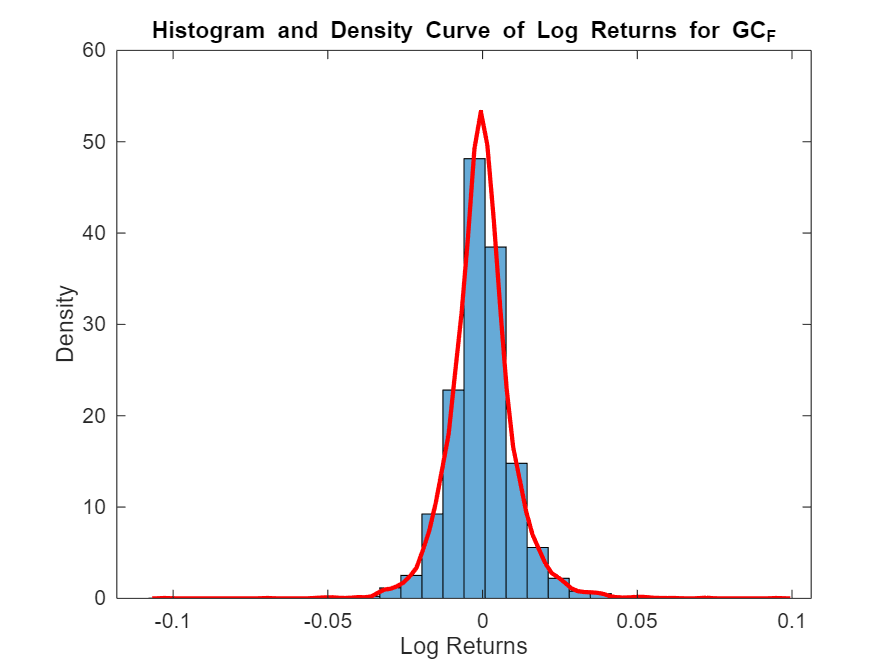

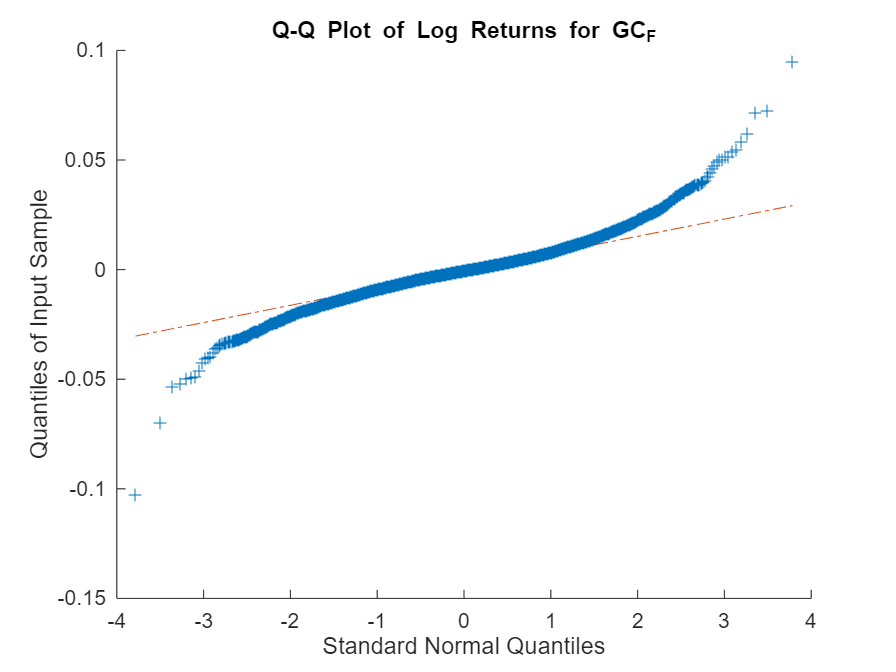

generatePlotsForAsset(LogReturns_GC_F, AssetName);

% iid Proprierties Test (Autocorrelation and Normality) - (Ljung-Box and D'Agostino-Pearson)
[autocorrResults, turningPointResults] = testIIDProperties(LogReturns_GC_F, AssetName)

            LjungBox_pValue    LjungBox_QStat    LjungBox_CritVal    Normality_pValue    JarqueBera_pValue    AutocorrelationConclusion    NormalityConclusion_JB    NormalityConclusion_DA
            _______________    ______________    ________________    ________________    _________________    _________________________    ______________________    ______________________

    GC_F        0.04399            18.718             18.307                0                  0.001             {'Autocorrelated'}            {'Not Normal'}            {'Not Normal'}    

            TurningPoints    ExpectedTurningPoints    ZScoreTurningPoints    PValueTur

autocorrResults = 1×8 table
            LjungBox_pValue    LjungBox_QStat    LjungBox_CritVal    Normality_pValue    JarqueBera_pValue    AutocorrelationConclusion    NormalityConclusion_JB    NormalityConclusion_DA
            _______________    ______________    ________________    ________________    _________________    _________________________    ______________________    ______________________

    GC_F        0.04399            18.718             18.307                0                  0.001             {'Autocorrelated'}            {'Not Normal'}            {'Not Normal'}    


turningPointResults = 1×6 table
            TurningPoints    ExpectedTurningPoints    ZScoreTurningPoints    PValueTurningPoints    IsIID    IIDConclusion
            _____________    _____________________    ___________________    ___________________    _____    _____________

    GC_F        4373                 3245                    33.21                    0             false     {'Not iid'} 


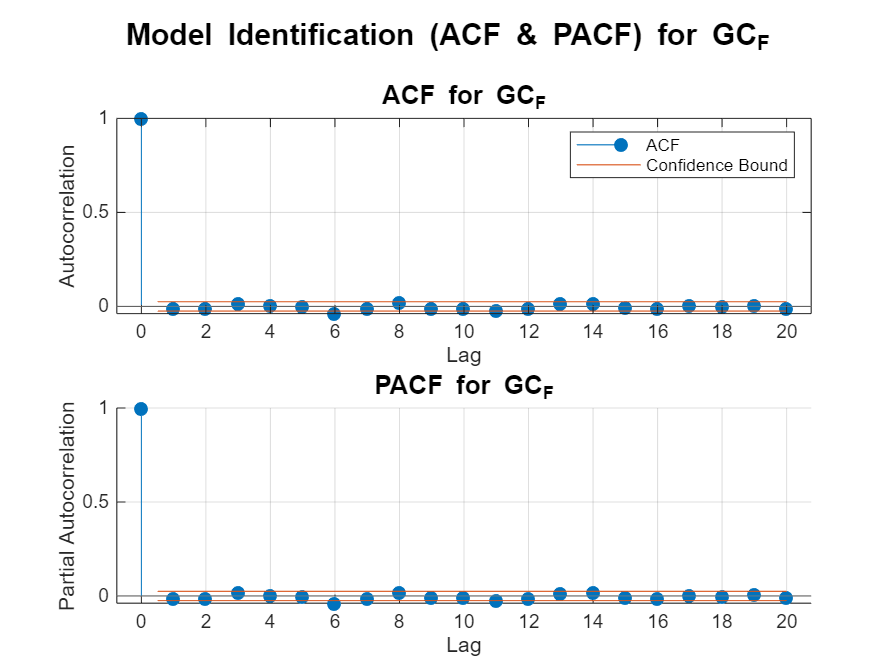

plotACFandPACF(LogReturns_GC_F, AssetName, 20)

% AR-GARCH
[ADFResults, AR_GARCHResults, stdResiduals, ResidualDiagnostics, AdditionalDiagnostics, EstModel, condVar] = AR_GARCH_Model_SingleAsset_tStudents(LogReturns_GC_F, AssetName)

ADFResults = 1×4 table
            pValue    TestStatistic    CriticalValue_5%    StationarityConclusion
            ______    _____________    ________________    ______________________

    GC_F    0.001        -81.492            -2.86               "Stationary"     


AR_GARCHResults = 1×14 table
    AssetName      AR1        ARCH1     GARCH1     Omega    Constant    DoF     SE_AR1    SE_ARCH1    SE_GARCH1    SE_Omega    SE_Constant    SE_DoF    ARCHplusGARCH
    _________    ________    _______    _______    _____    ________    ____    ______    ________    _________    ________    ___________    ______    _____________

    {'GC_F'}     -0.01787    0.04785    0.94107      0      -0.00043    5.42    0.0001    0.01262         0        0.00617       0.00513       0.4         0.98892

stdResiduals =    -1.3601
   -3.0592
   -0.0119
    1.5205
    2.0401
    0.5093
   -0.4601
    0.2753
   -0.9367
   -0.7001


ResidualDiagnostics = 1×4 table
            LjungBox_Resids_pVal    LjungBox_ResidsSq_pVal    TurningPoint_pVal    iidConclusion
            ____________________    ______________________    _________________    _____________

    GC_F          0.40485                   0.9986                 0.33126           "i.i.d."   


AdditionalDiagnostics = 1×5 table
            ARCH_pValue    ARCH_TestStatistic    ARCH_CriticalValue_5%    JB_pValue    JB_TestStatistic
            ___________    __________________    _____________________    _________    ________________

    GC_F      0.96502           0.96904                  11.07              0.001           1499.1     


EstModel = 1×6 table
            VaR_95     CVaR_95    VaR_97     CVaR_97    VaR_99     CVaR_99
            _______    _______    _______    _______    _______    _______

    GC_F    -1.1272    -1.1663    -1.3571    -1.1379    -1.8821    -1.0244


condVar =   arima with properties:

     Description: "ARIMA(1,0,0) Model (t Distribution)"
      SeriesName: "Y"
    Distribution: Name = "t", DoF = 5.41727
               P: 1
               D: 0
               Q: 0
        Constant: -0.000433021
              AR: {-0.0178741} at lag [1]
             SAR: {}
              MA: {}
             SMA: {}
     Seasonality: 0
            Beta: [1×0]
        Variance: [GARCH(1,1) Model]

% ME PLOT before EVT
plotMeanExcess(stdResiduals, AssetName, 100);

% threshold selection manually
outDir = 'THRESHOLD';
thresholds = 90:1:99; 
p = [0.95, 0.975, 0.99];
leftTail = true;
threshold_selection(stdResiduals, AssetName, thresholds, p, outDir, leftTail);

% EVT
threshold=[0.96, 0.97];
opts.leftTail = true;
EVT_Results=EVT_POT_Model_Simplified(stdResiduals, AssetName, threshold, opts)

Risultati EVT POT per asset: GC_F
    ThresholdLevel    Threshold_u    NumExceedances      xi        sigma      VaR       CVaR     AD_stat    CvM_stat    AD_pValue    CvM_pValue    Kupiec_pValue    ObservedHitRate    Kupiec_Stat
    ______________    ___________    ______________    _______    _______    ______    ______    _______    ________    _________    __________    _____________    _______________    ___________

         0.96           1.6728            260          0.13547    0.45123    1.6734    2.1952    0.

EVT_Results = struct with fields:
    OutTable: [2×14 table]


% Reconstruct VaR and ES
CI = [0.95, 0.975, 0.99];
EVT_VaR_ES = Reconstruct_EVT_VaR_ES(AssetName, EVT_Results, CI);
disp(EVT_VaR_ES);

            VaR_95      ES_95     VaR_98     ES_98     VaR_99     ES_99 
            _______    _______    _______    ______    _______    ______

    GC_F    -1.6734    -2.1952    -1.7983    -2.349    -1.7983    -2.349



% PLOT EVT results
outputDir = 'results_gold_EVT';
VaR_levels = [0.95 0.97 0.99];
analyzeEVTPlots_Pro(stdResiduals, EVT_Results, outputDir, VaR_levels);

% BACKTESTING:  CRISIS 2008
rollingWindow = 500;
nSimulations = 100000;
confidenceLevels = [0.95,0.975, 0.99];

% Crisis 2008
startDate2008 = datetime(2007,1,1);
endDate2008   = datetime(2009,12,31);
% Filter
idx2008 = (Dates_GC_F >= startDate2008) & (Dates_GC_F <= endDate2008);
Dates_2008      = Dates_GC_F(idx2008);
stdResids_2008  = stdResiduals(idx2008);

%% Parametri opzionali
ThresholdLevel   = 0.96;  
OutDir="Backtest_Crisis_2008_GOLD";

[BacktestResults_2008, VaR_sim_2008, ES_sim_2008, RealResidues_2008, CI_Low_2008, CI_High_2008] = ...
    backtestingMonteCarloDiagnostics(stdResids_2008, Dates_2008, rollingWindow, nSimulations, confidenceLevels, ...
                                     startDate2008, endDate2008, ThresholdLevel,OutDir);

=== Backtest Summary ===
    ConfidenceLevel    MeanVaR    MeanES    ViolationRate      CI_Low      CI_High 
    _______________    _______    ______    _____________    __________    ________

          0.95         1.7636     2.2137       0.042254        0.022021    0.072645
         0.975         2.1039     2.5097       0.014085       0.0038505    0.035667
          0.99         2.4975      2.861      0.0070423      0.00085399    0.025206

=== Diagnostics Tests ===
    ConfidenceLevel    Kupiec_LR    Kupiec_pValue    Kupiec_ModelAccepted    Christ_LR    Christ_pValue    Christ_ModelAccepted
    _______________    _________    

% BACKTESTING COVID-19 
rollingWindow2 = 250;
nSimulations2 = 100000;
confidenceLevels2 = [0.95,0.97, 0.99];

% Covid-19
startDateCOVID = datetime(2020,2,1);
endDateCOVID = datetime(2021,7,31);
% Filter
idxCOVID = (Dates_GC_F >= startDateCOVID) & (Dates_GC_F <= endDateCOVID);
Dates_COVID      = Dates_GC_F(idxCOVID);
stdResids_COVID  = stdResiduals(idxCOVID);

%% Parametri opzionali
ThresholdLevel   = 0.96;                  
OutDir           = 'Backtesting_Covid_GOLD';

[BacktestResults_COVID, VaR_sim_COVID, ES_sim_COVID, RealResidues_COVID, CI_Low_COVID, CI_High_COVID] = ...
    backtestingMonteCarloDiagnostics(stdResids_COVID, Dates_COVID, rollingWindow2, nSimulations2, confidenceLevels2, ...
    startDateCOVID, endDateCOVID, ThresholdLevel,OutDir);

=== Backtest Summary ===
    ConfidenceLevel    MeanVaR    MeanES    ViolationRate      CI_Low      CI_High 
    _______________    _______    ______    _____________    __________    ________

         0.95          1.7011     2.1506        0.05036        0.020484     0.10101
         0.97          1.9549     2.3715       0.035971        0.011781    0.081947
         0.99          2.4343     2.7986      0.0071942      0.00018213    0.039431

=== Diagnostics Tests ===
    ConfidenceLevel    Kupiec_LR     Kupiec_pValue    Kupiec_ModelAccepted    Christ_LR    Christ_pValue    Christ_ModelAccepted
    _______________    __________    

% BACKTESTING Energy Crisis (2022)

rollingWindow3 = 250;
nSimulations3 = 100000;
confidenceLevels3 = [0.95,0.97, 0.99];

% Covid-19
startDateEnergyCrisis = datetime(2021,8,1);
endDateEnergyCrisis   = datetime(2022,12,31);
% Filter
idxEnergyCrisis = (Dates_GC_F >= startDateEnergyCrisis) & (Dates_GC_F <= endDateEnergyCrisis);
Dates_EnergyCrisis      = Dates_GC_F(idxEnergyCrisis);
stdResids_EnergyCrisis  = stdResiduals(idxEnergyCrisis);

%% Parametri opzionali
ThresholdLevel   = 0.96;            
OutDir           = 'Backtest_Energy_GOLD';



[BacktestResults_Energy, VaR_sim_Energy, ES_sim_Energy, RealResidues_Energy, CI_Low_Energy, CI_High_Energy] = ...
    backtestingMonteCarloDiagnostics(stdResids_EnergyCrisis, Dates_EnergyCrisis, rollingWindow3, nSimulations3, confidenceLevels3, ...
    startDateEnergyCrisis, endDateEnergyCrisis, ThresholdLevel,OutDir);

=== Backtest Summary ===
    ConfidenceLevel    MeanVaR    MeanES    ViolationRate     CI_Low      CI_High 
    _______________    _______    ______    _____________    _________    ________

         0.95          1.4888     1.8946       0.07563        0.035165     0.13872
         0.97          1.7181     2.0939      0.033613       0.0092331    0.083829
         0.99          2.1508     2.4795      0.016807       0.0020419    0.059393

=== Diagnostics Tests ===
    ConfidenceLevel    Kupiec_LR    Kupiec_pValue    Kupiec_ModelAccepted    Christ_LR    Christ_pValue    Christ_ModelAccepted
    _______________    _________    ___

## **ANALYSIS BRENT**

% Input
AssetName_BRENT = Names{1,2};
Prices_BRENT = Prices(:, 2);  
LogReturns_BRENT = diff(log(Prices_BRENT)); 
Dates_BRENT = Dates(2:end); 

% Risk measures
calculateRiskStats(LogReturns_BRENT, AssetName_BRENT)

       Asset Name        Number_of_Returns    Mean (%)    StdDev (%)    Variance (%)    Kurtosis    Skewness    VaR_95    CVaR_95    VaR_97     CVaR_97    VaR_99     CVaR_99
    _________________    _________________    ________    __________    ____________    ________    ________    ______    _______    _______    _______    _______    _______

    {'BrentCrudeOil'}          6491           -0.0147       2.2991         0.0529        13.464      0.6202     -3.767    -4.7276    -4.3094    -5.1998    -5.3338    -6.1128



ans = 1×13 table
       Asset Name        Number_of_Returns    Mean (%)    StdDev (%)    Variance (%)    Kurtosis    Skewness    VaR_95    CVaR_95    VaR_97     CVaR_97    VaR_99     CVaR_99
    _________________    _________________    ________    __________    ____________    ________    ________    ______    _______    _______    _______    _______    _______

    {'BrentCrudeOil'}          6491           -0.0147       2.2991         0.0529        13.464      0.6202     -3.767    -4.7276    -4.3094    -5.1998    -5.3338    -6.1128


% iid Proprierties Test (Autocorrelation and Normality) - (Ljung-Box and D'Agostino-Pearson)
[autocorrResults_BRENT, turningPointResults_BRENT] = testIIDProperties(LogReturns_BRENT, AssetName_BRENT)

                     LjungBox_pValue    LjungBox_QStat    LjungBox_CritVal    Normality_pValue    JarqueBera_pValue    AutocorrelationConclusion    NormalityConclusion_JB    NormalityConclusion_DA
                     _______________    ______________    ________________    ________________    _________________    _________________________    ______________________    ______________________

    BrentCrudeOil       0.091052            16.312             18.307                0                  0.001            {'No-Autocorrelated'}          {'Not Normal'}            {'Not Normal'}    

                     TurningPoints    ExpectedTurningPoints    ZScoreTurning

autocorrResults_BRENT = 1×8 table
                     LjungBox_pValue    LjungBox_QStat    LjungBox_CritVal    Normality_pValue    JarqueBera_pValue    AutocorrelationConclusion    NormalityConclusion_JB    NormalityConclusion_DA
                     _______________    ______________    ________________    ________________    _________________    _________________________    ______________________    ______________________

    BrentCrudeOil       0.091052            16.312             18.307                0                  0.001            {'No-Autocorrelated'}          {'Not Normal'}            {'Not Normal'}    


turningPointResults_BRENT = 1×6 table
                     TurningPoints    ExpectedTurningPoints    ZScoreTurningPoints    PValueTurningPoints    IsIID    IIDConclusion
                     _____________    _____________________    ___________________    ___________________    _____    _____________

    BrentCrudeOil        4363                 3245                   32.916                    0             false     {'Not iid'} 


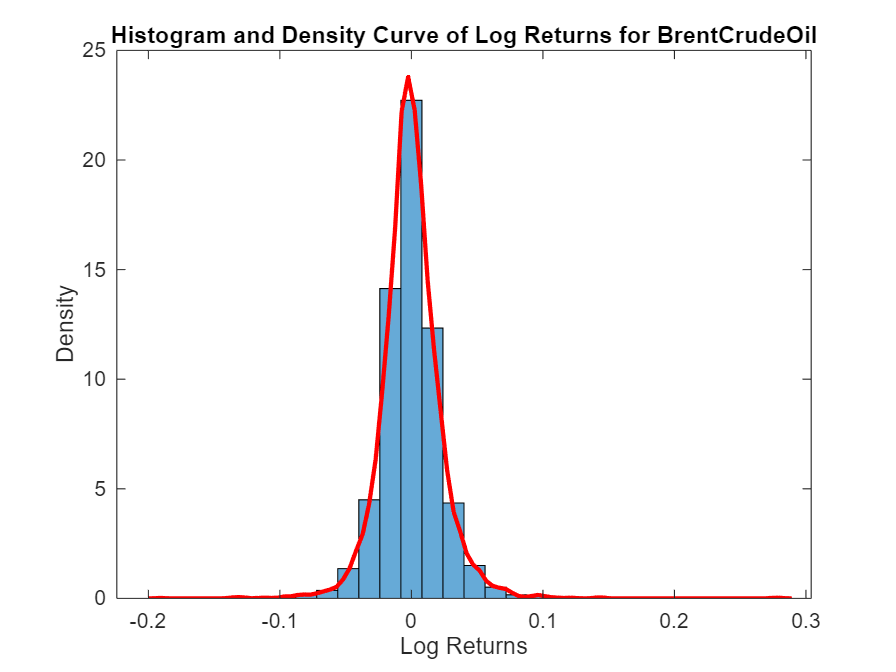

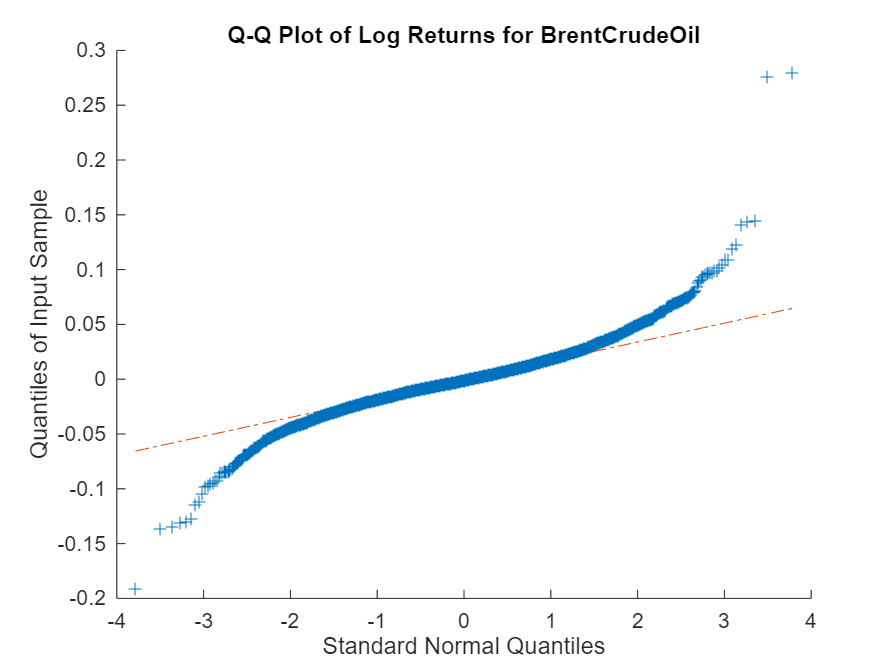

generatePlotsForAsset(LogReturns_BRENT, AssetName_BRENT);

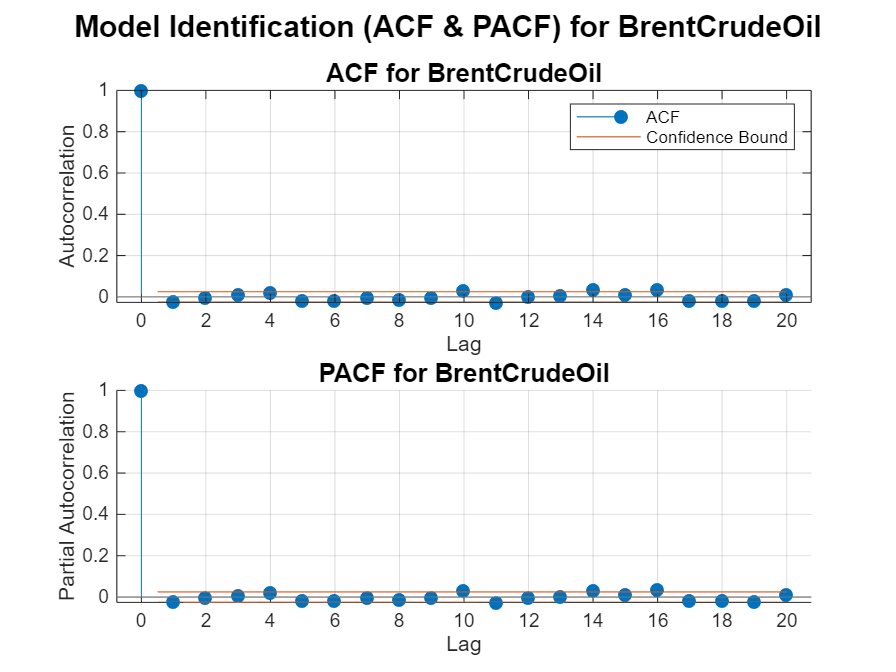

plotACFandPACF(LogReturns_BRENT, AssetName_BRENT, 20)

% AR-GARCH
[ADFResults_BRENT, AR_GARCHResults_BRENT, stdResiduals_BRENT, ResidualDiagnostics_BRENT, AdditionalDiagnostics_BRENT, EstModel_BRENT, condVar_BRENT] = AR_GARCH_Model_SingleAsset_tStudents(LogReturns_BRENT, AssetName_BRENT)

ADFResults_BRENT = 1×4 table
                     pValue    TestStatistic    CriticalValue_5%    StationarityConclusion
                     ______    _____________    ________________    ______________________

    BrentCrudeOil    0.001        -82.244            -2.86               "Stationary"     


AR_GARCHResults_BRENT = 1×14 table
        AssetName          AR1        ARCH1     GARCH1     Omega    Constant    DoF     SE_AR1     SE_ARCH1    SE_GARCH1    SE_Omega    SE_Constant    SE_DoF    ARCHplusGARCH
    _________________    ________    _______    _______    _____    ________    ____    _______    ________    _________    ________    ___________    ______    _____________

    {'BrentCrudeOil'}    -0.02793    0.08451    0.90572    1e-05    -0.00077    7.17    0.00021    0.01278         0        0.00774       

stdResiduals_BRENT =     1.4820
   -1.6451
    0.8311
    0.8814
    2.7133
    2.2007
   -0.0980
    0.1148
   -0.4292
    0.1825


ResidualDiagnostics_BRENT = 1×4 table
                     LjungBox_Resids_pVal    LjungBox_ResidsSq_pVal    TurningPoint_pVal    iidConclusion
                     ____________________    ______________________    _________________    _____________

    BrentCrudeOil          0.68567                  0.84452                 0.92962           "i.i.d."   


AdditionalDiagnostics_BRENT = 1×5 table
                     ARCH_pValue    ARCH_TestStatistic    ARCH_CriticalValue_5%    JB_pValue    JB_TestStatistic
                     ___________    __________________    _____________________    _________    ________________

    BrentCrudeOil      0.81903            2.2125                  11.07              0.001           611.32     


EstModel_BRENT = 1×6 table
                     VaR_95     CVaR_95    VaR_97     CVaR_97    VaR_99     CVaR_99
                     _______    _______    _______    _______    _______    _______

    BrentCrudeOil    -3.1186    -3.3571    -3.6994    -3.3765    -4.9647    -3.2506


condVar_BRENT =   arima with properties:

     Description: "ARIMA(1,0,0) Model (t Distribution)"
      SeriesName: "Y"
    Distribution: Name = "t", DoF = 7.16787
               P: 1
               D: 0
               Q: 0
        Constant: -0.000771491
              AR: {-0.0279262} at lag [1]
             SAR: {}
              MA: {}
             SMA: {}
     Seasonality: 0
            Beta: [1×0]
        Variance: [GARCH(1,1) Model]

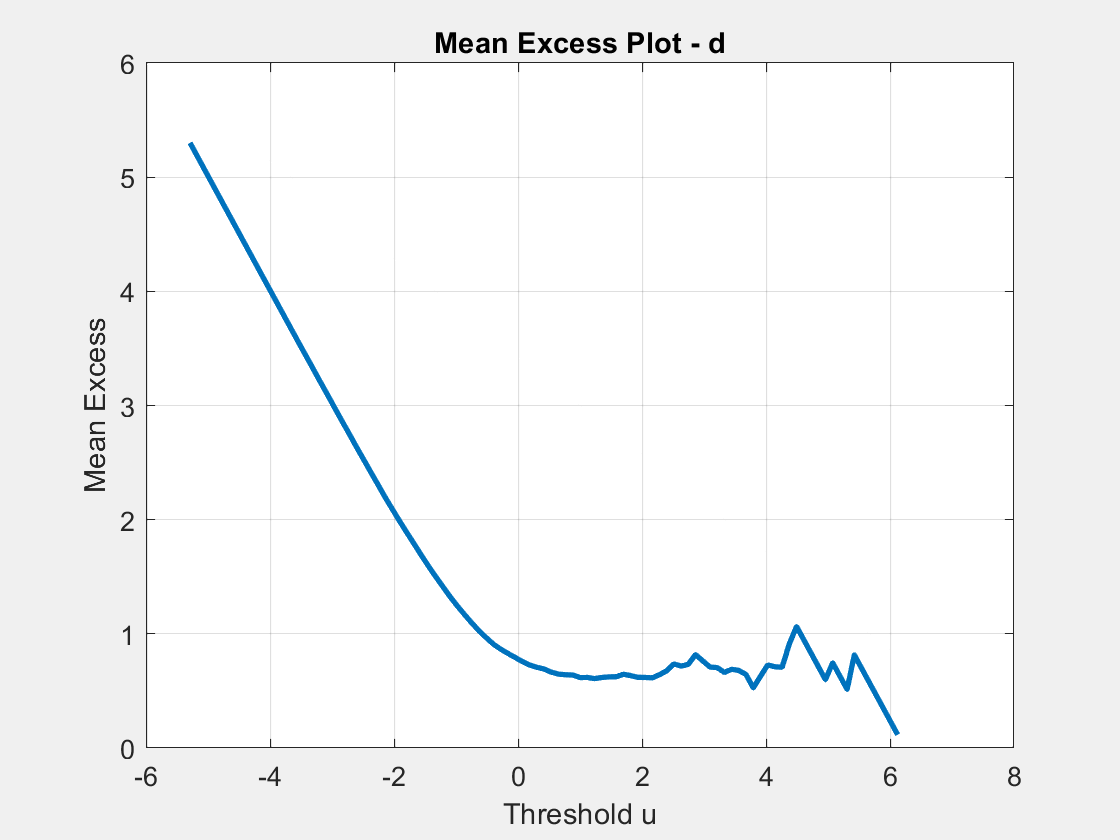

Mean Excess plot salvato in: BrentCrudeOil\MeanExcess_d.png


% ME PLOT
plotMeanExcess(stdResiduals_BRENT, AssetName_BRENT, 100);

% Threshold selection
outDir = 'THRESHOLD';
thresholds = 90:1:99; 
p = [0.95, 0.975, 0.99];
leftTail = true;
threshold_selection(stdResiduals_BRENT, AssetName_BRENT, thresholds, p, outDir, leftTail);

✅ Grafici salvati in: THRESHOLD


% EVT
threshold_BRENT=[0.95, 0.97];
opts.leftTail = true;
EVT_Results_BRENT=EVT_POT_Model_Simplified(stdResiduals_BRENT, AssetName_BRENT, threshold_BRENT, opts)

Risultati EVT POT per asset: BrentCrudeOil
    ThresholdLevel    Threshold_u    NumExceedances        xi         sigma      VaR       CVaR     AD_stat    CvM_stat    AD_pValue    CvM_pValue    Kupiec_pValue    ObservedHitRate    Kupiec_Stat
    ______________    ___________    ______________    __________    _______    ______    ______    _______    ________    _________    __________    _____________    _______________    ___________

         0.95           1.6106            325          1.9934e-05    0.50146    1.61

EVT_Results_BRENT = struct with fields:
    OutTable: [2×14 table]


EVT_OutTable=EVT_Results.OutTable;

% Reconstruct VaR and ES
threshold_BRENT = [0.95, 0.97, 0.99];
EVT_VaR_ES = Reconstruct_EVT_VaR_ES(AssetName_BRENT, EVT_Results_BRENT, threshold_BRENT);
disp(EVT_VaR_ES);

                     VaR_95      ES_95     VaR_97      ES_97     VaR_99      ES_99 
                     _______    _______    _______    _______    _______    _______

    BrentCrudeOil    -1.6113    -2.1127    -1.8732    -2.3645    -1.8732    -2.3645



% PLOT EVT results

outputDir = 'results_brent_EVT';
VaR_levels = [0.95 0.97 0.99];
analyzeEVTPlots_Pro(stdResiduals_BRENT, EVT_Results_BRENT, outputDir, VaR_levels);

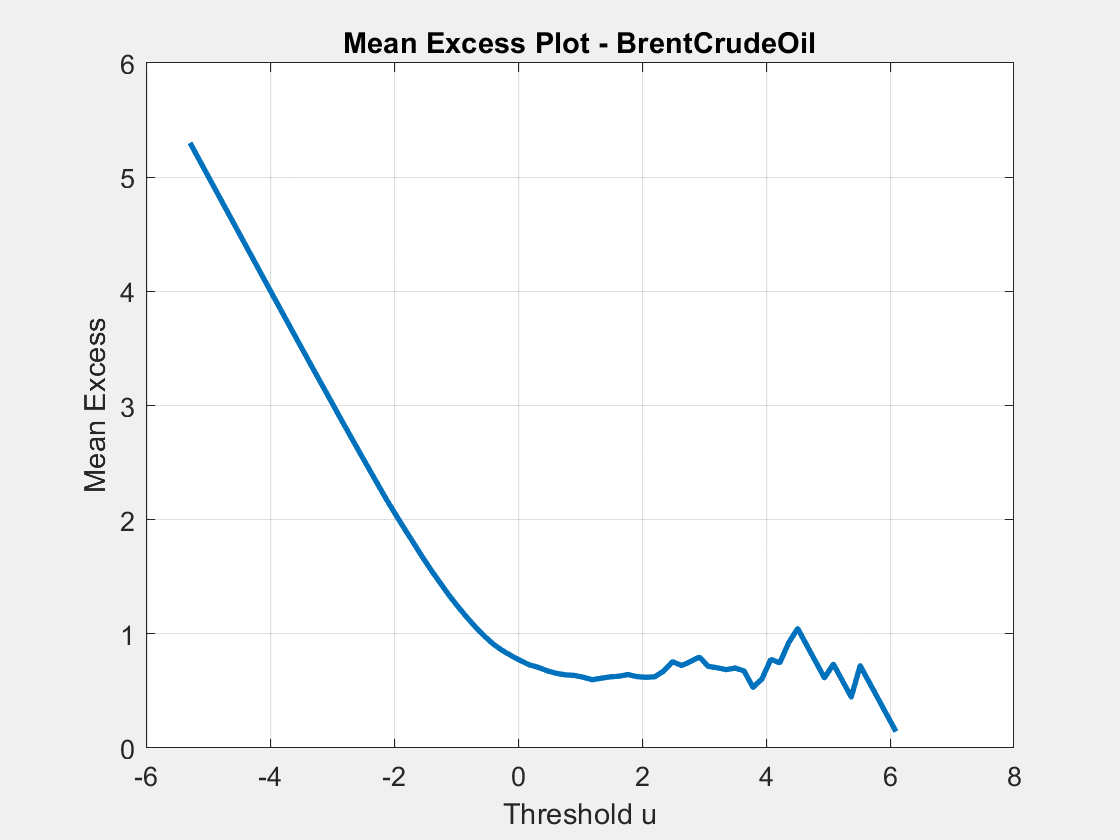

Mean Excess plot salvato in: plots_Gold\MeanExcess_BrentCrudeOil.png


% ME PLOT 
plotMeanExcess(stdResiduals_BRENT, 'plots_Gold', 'BrentCrudeOil',nPoints);

% BACKTESTING:  CRISIS 2008
rollingWindow_BRENT = 250;
nSimulations_BRENT = 1000;
confidenceLevels_BRENT = [0.95, 0.975, 0.99];

% 2008 Crisis
startDate2008_BRENT = datetime(2007,1,1);
endDate2008_BRENT   = datetime(2009,12,31);
% Filter
idx2008_BRENT = (Dates_BRENT>= startDate2008_BRENT) & (Dates_BRENT <= endDate2008_BRENT);
Dates_2008_BRENT      = Dates_BRENT(idx2008_BRENT);
stdResids_2008_BRENT  = stdResiduals_BRENT(idx2008_BRENT);

%% Parametri opzionali
ThresholdLevel_BRENT   = 0.95;          
OutDir_BRENT           = 'Backtest_Crisis_2008_BRENT';
 

[BacktestResults_BRENT_2008, VaR_sim_BRENT_2008, ES_sim_BRENT_2008, RealResidues_BRENT_2008, CI_Low_BRENT_2008, CI_High_BRENT_2008] = ...
    backtestingMonteCarloDiagnostics(stdResids_2008_BRENT, Dates_2008_BRENT, rollingWindow_BRENT, nSimulations_BRENT, confidenceLevels_BRENT, ...
    startDate2008_BRENT, endDate2008_BRENT, ThresholdLevel_BRENT,OutDir_BRENT);

=== Backtest Summary ===
    ConfidenceLevel    MeanVaR    MeanES    ViolationRate     CI_Low      CI_High 
    _______________    _______    ______    _____________    _________    ________

          0.95         1.6457     2.0672       0.043071       0.027496    0.063929
         0.975         1.9643     2.3445       0.016854      0.0077349    0.031752
          0.99         2.3392     2.6701      0.0074906      0.0020446    0.019067

=== Diagnostics Tests ===
    ConfidenceLevel    Kupiec_LR    Kupiec_pValue    Kupiec_ModelAccepted    Christ_LR     Christ_pValue    Christ_ModelAccepted
    _______________    _________    __

% BACKTESTING:  COVID
rollingWindow2_BRENT = 250;
nSimulations2_BRENT = 1000;
confidenceLevels2_BRENT = [0.95, 0.975, 0.99];

% covid
startDateCOVID_BRENT = datetime(2020,2,1);
endDateCOVID_BRENT = datetime(2021,7,31);
% Filter
idxCOVID_BRENT = (Dates_BRENT >= startDateCOVID_BRENT) & (Dates_BRENT <= endDateCOVID_BRENT);
Dates_COVID_BRENT      = Dates_BRENT(idxCOVID_BRENT);
stdResids_COVID_BRENT  = stdResiduals_BRENT(idxCOVID_BRENT);

%% Parametri opzionali
ThresholdLevel_BRENT   = 0.95;              
OutDir_BRENT           = 'Backtesting_Covid_BRENT';


% APPLICATION
[BacktestResults_BRENT_Covid, VaR_sim_BRENT_Covid, ES_sim_BRENT_Covid, RealResidues_BRENT_Covid, CI_Low_BRENT_Covid, CI_High_BRENT_Covid] = ...
    backtestingMonteCarloDiagnostics(stdResids_COVID_BRENT, Dates_COVID_BRENT, rollingWindow2_BRENT, nSimulations2_BRENT, confidenceLevels2_BRENT, ...
    startDateCOVID_BRENT, endDateCOVID_BRENT, ThresholdLevel_BRENT,OutDir_BRENT);

=== Backtest Summary ===
    ConfidenceLevel    MeanVaR    MeanES    ViolationRate     CI_Low      CI_High 
    _______________    _______    ______    _____________    _________    ________

          0.95         1.8164     2.2659      0.071942        0.035037     0.12832
         0.975         2.1654     2.5569      0.035971        0.011781    0.081947
          0.99         2.5519     2.8873      0.014388       0.0017473    0.051008

=== Diagnostics Tests ===
    ConfidenceLevel    Kupiec_LR    Kupiec_pValue    Kupiec_ModelAccepted    Christ_LR    Christ_pValue    Christ_ModelAccepted
    _______________    _________    ___

% BACKTESTING:  Energy Crisis(2022)
rollingWindow3_BRENT = 250;
nSimulations3_BRENT = 1000;
confidenceLevels3_BRENT = [0.95, 0.975, 0.99];

% Energy Crisis(2022)
startDateEnergyCrisis_BRENT = datetime(2021,8,1);
endDateEnergyCrisis_BRENT   = datetime(2022,12,31);
% Filter
idxEnergyCrisis_BRENT = (Dates_BRENT >= startDateEnergyCrisis_BRENT) & (Dates_BRENT <= endDateEnergyCrisis_BRENT);
Dates_EnergyCrisis_BRENT      = Dates_BRENT(idxEnergyCrisis_BRENT);
stdResids_EnergyCrisis_BRENT  = stdResiduals_BRENT(idxEnergyCrisis_BRENT);

%% Parametri opzionali
ThresholdLevel_BRENT   = 0.94;                  
OutDir_BRENT           = 'Backtesting_Ukraine_BRENT'; 

% APPLICATION
[BacktestResults_BRENT_Energy, VaR_sim_BRENT_Energy, ES_sim_BRENT_Energy, RealResidues_BRENT_Energy, CI_Low_BRENT_Energy, CI_High_BRENT_Energy] = ...
    backtestingMonteCarloDiagnostics(stdResids_EnergyCrisis_BRENT, Dates_EnergyCrisis_BRENT, rollingWindow3_BRENT, nSimulations3_BRENT, confidenceLevels3_BRENT, ...
    startDateEnergyCrisis_BRENT, endDateEnergyCrisis_BRENT, ThresholdLevel_BRENT,OutDir_BRENT);

=== Backtest Summary ===
    ConfidenceLevel    MeanVaR    MeanES    ViolationRate     CI_Low      CI_High 
    _______________    _______    ______    _____________    _________    ________

          0.95          1.704     2.1435      0.058824        0.023975     0.11745
         0.975         2.0422     2.4294       0.02521       0.0052294    0.071908
          0.99         2.4194     2.7578      0.016807       0.0020419    0.059393

=== Diagnostics Tests ===
    ConfidenceLevel    Kupiec_LR     Kupiec_pValue    Kupiec_ModelAccepted    Christ_LR    Christ_pValue    Christ_ModelAccepted
    _______________    __________    _

% BACKTESTING:  IRAN CONFLICT(2026)
rollingWindow3_IRAN = 250;
nSimulations3_IRAN = 1000;
confidenceLevels3_IRAN = [0.95, 0.975, 0.99];

% Energy Crisis(2022)
startDateEnergyCrisis_IRAN = datetime(2026,1,1);
endDateEnergyCrisis_IRAN   = datetime(2022,3,13);
% Filter
idxEnergyCrisis_IRAN = (Dates_IRAN >= startDateEnergyCrisis_IRAN) & (Dates_IRAN <= endDateEnergyCrisis_IRAN);

Unrecognized function or variable 'Dates_IRAN'.

Dates_EnergyCrisis_IRAN      = Dates_IRAN(idxEnergyCrisis_IRAN);
stdResids_EnergyCrisis_IRAN  = stdResiduals_IRAN(idxEnergyCrisis_IRAN);

%% Parametri opzionali
ThresholdLevel_IRAN   = 0.94;                  
OutDir_IRAN           = 'Backtesting_Ukraine_IRAN'; 

% APPLICATION
[BacktestResults_IRAN, VaR_sim_IRAN, ES_sim_IRAN, RealResidues_IRAN, CI_Low_IRAN, CI_High_IRAN] = ...
    backtestingMonteCarloDiagnostics(stdResids_EnergyCrisis_IRAN, Dates_EnergyCrisis_IRAN, rollingWindow3_IRAN, nSimulations3_IRAN, confidenceLevels3_IRAN, ...
    startDateEnergyCrisis_IRAN, endDateEnergyCrisis_IRAN, ThresholdLevel_IRAN,OutDir_IRAN);





%% Parametri modificabili - AGGIUNTI NUOVI PARAMETRI VISIVI
window = 65;            
method = 'movstd';      
spike_method = 'zscore';
z_thresh = 2;          
perc_thresh = 95;       

% Nuovi parametri per styling
crisis_alpha = 0.20;        % Trasparenza bande crisi
vol_linewidth = 1.5;        % Spessore linea volatilità
zscore_linewidth = 1;       % Spessore linea z-score
spike_markersize = 4;       % Dimensione marcatori spike
font_size = 11;             % Dimensione font generale
crisis_font_size = 6;       % Dimensione font etichette crisi
legend_font_size = 8;       % RIDOTTA dimensione font legenda

% Definisci colori consistenti
colors = struct();
colors.gold_vol = [0.8, 0.6, 0.2];      % Oro
colors.brent_vol = [0.1, 0.5, 0.8];     % Blu Brent
colors.gold_z = [0.9, 0.8, 0.3];        % Oro chiaro z-score
colors.brent_z = [0.4, 0.7, 1.0];       % Blu chiaro z-score
colors.spike = [0.9, 0.1, 0.1];         % Rosso per spike
colors.spike_normal = [0.2, 0.6, 0.2];  % VERDE per spike normali (nuovo colore)
colors.crisis = [0.95, 0.85, 0.6];      % Colore bande crisi

% Periodi di crisi (modifica se preferisci altri intervalli)
crisisPeriods = {
    datetime(2008,9,1),  datetime(2009,3,31),  'Global Financial Crisis';
    datetime(2020,2,20), datetime(2020,5,1),   'COVID shock';
    datetime(2022,2,24), datetime(2022,6,30),  'Ukraine war'
};

%% Allineo le date (se le serie hanno la stessa frequenza dovrebbe andare ok)
% prendo l'intersezione dei Date arrays nel caso siano leggermente diversi
commonDates = intersect(Dates_GC_F, Dates_BRENT);
if isempty(commonDates)
    % se non c'è intersezione, uso la più lunga (attenzione)
    commonDates = Dates_GC_F;
end

% ricampiona o allinea le returns alle commonDates
[~, ia] = ismember(commonDates, Dates_GC_F);
[~, ib] = ismember(commonDates, Dates_BRENT);
r1 = NaN(size(commonDates));
r2 = NaN(size(commonDates));
r1(ia>0) = LogReturns_GC_F(ia(ia>0));   % Gold
r2(ib>0) = LogReturns_BRENT(ib(ib>0));  % Brent

% rimuovo NaN estreme
validMask = ~isnan(r1) & ~isnan(r2);
commonDates = commonDates(validMask);
r1 = r1(validMask);
r2 = r2(validMask);

%% Calcolo volatilità rolling (semplice std mobile)
vol1 = movstd(r1, window, 'omitnan');   % volatilità Gold
vol2 = movstd(r2, window, 'omitnan');   % volatilità Brent

% Normalizzo per confrontare (z-score)
vol1_z = (vol1 - nanmean(vol1)) ./ nanstd(vol1);
vol2_z = (vol2 - nanmean(vol2)) ./ nanstd(vol2);

%% Individuazione spike - QUESTA SEZIONE MANCAVA!
switch spike_method
    case 'zscore'
        spikes1 = vol1_z > z_thresh;
        spikes2 = vol2_z > z_thresh;
    case 'percentile'
        t1 = prctile(vol1(~isnan(vol1)), perc_thresh);
        t2 = prctile(vol2(~isnan(vol2)), perc_thresh);
        spikes1 = vol1 > t1;
        spikes2 = vol2 > t2;
    otherwise
        error('spike_method sconosciuto');
end

%% Identifica quali spike cadono nei periodi di crisi
% Per Gold
spike_dates1 = commonDates(spikes1);
spike_vals1 = vol1(spikes1);

is_crisis_spike1 = false(size(spike_dates1));
for k = 1:size(crisisPeriods, 1)
    crisis_start = crisisPeriods{k, 1};
    crisis_end = crisisPeriods{k, 2};
    in_crisis = (spike_dates1 >= crisis_start) & (spike_dates1 <= crisis_end);
    is_crisis_spike1 = is_crisis_spike1 | in_crisis;
end

% Per Brent
spike_dates2 = commonDates(spikes2);
spike_vals2 = vol2(spikes2);

is_crisis_spike2 = false(size(spike_dates2));
for k = 1:size(crisisPeriods, 1)
    crisis_start = crisisPeriods{k, 1};
    crisis_end = crisisPeriods{k, 2};
    in_crisis = (spike_dates2 >= crisis_start) & (spike_dates2 <= crisis_end);
    is_crisis_spike2 = is_crisis_spike2 | in_crisis;
end

%% Plot principale - VERSIONE MIGLIORATA
figure('Position', [100 100 1200 800], 'Color', 'white');

% Pannello 1: Gold
subplot(2,1,1);
hold on; grid on;

% Bande crisi con colori migliori
yl = [min([vol1; vol2],[],'omitnan'), max([vol1; vol2],[],'omitnan')];
for k = 1:size(crisisPeriods,1)
    x1 = crisisPeriods{k,1}; x2 = crisisPeriods{k,2}; 
    lbl = crisisPeriods{k,3};
    patch([x1 x2 x2 x1], [yl(1) yl(1) yl(2) yl(2)], ...
          colors.crisis, 'FaceAlpha', crisis_alpha, ...
          'EdgeColor', [0.7 0.7 0.7], 'LineWidth', 0.5);
end

% Plot linee principali
p_vol1 = plot(commonDates, vol1, 'LineWidth', vol_linewidth, ...
              'Color', colors.gold_vol, ...
              'DisplayName', 'Vol (rolling)');
p_z1 = plot(commonDates, vol1_z, '--', 'LineWidth', zscore_linewidth, ...
            'Color', colors.gold_z, ...
            'DisplayName', 'Vol (z-score)');

% Spike con DUE COLORI diversi
% Spike durante le crisi (rosso)
p_spike1_crisis = plot(spike_dates1(is_crisis_spike1), spike_vals1(is_crisis_spike1), 'o', ...
               'MarkerSize', spike_markersize, ...
               'MarkerFaceColor', colors.spike, ...
               'MarkerEdgeColor', 'black', ...
               'LineWidth', 1, ...
               'DisplayName', 'Spike (Crisis)');

% Spike normali (verde)
p_spike1_normal = plot(spike_dates1(~is_crisis_spike1), spike_vals1(~is_crisis_spike1), 'o', ...
               'MarkerSize', spike_markersize, ...
               'MarkerFaceColor', colors.spike_normal, ...
               'MarkerEdgeColor', 'black', ...
               'LineWidth', 1, ...
               'DisplayName', 'Spike (Normal)');

title('Rolling Volatility - Gold', 'FontSize', font_size+2, 'FontWeight', 'bold');
ylabel('Volatility (std of log-returns)', 'FontSize', font_size);

% LEGENDA RIDOTTA
%legend('Location', 'northeast', 'FontSize', legend_font_size, ...
     %  'NumColumns', 1, 'Box', 'on');

xlim([commonDates(1) commonDates(end)]);

% Migliora assi
set(gca, 'FontSize', font_size, 'GridAlpha', 0.3, ...
         'TickLabelInterpreter', 'none');

hold off;

% Pannello 2: Brent
subplot(2,1,2);
hold on; grid on;

% Bande crisi (stesso stile del primo pannello)
for k = 1:size(crisisPeriods,1)
    x1 = crisisPeriods{k,1}; x2 = crisisPeriods{k,2};
    patch([x1 x2 x2 x1], [yl(1) yl(1) yl(2) yl(2)], ...
          colors.crisis, 'FaceAlpha', crisis_alpha, ...
          'EdgeColor', [0.7 0.7 0.7], 'LineWidth', 0.5);
end

% Plot linee principali
p_vol2 = plot(commonDates, vol2, 'LineWidth', vol_linewidth, ...
              'Color', colors.brent_vol, ...
              'DisplayName', 'Vol (rolling)');
p_z2 = plot(commonDates, vol2_z, '--', 'LineWidth', zscore_linewidth, ...
            'Color', colors.brent_z, ...
            'DisplayName', 'Vol (z-score)');

% Spike con DUE COLORI diversi per Brent
% Spike durante le crisi (rosso)
p_spike2_crisis = plot(spike_dates2(is_crisis_spike2), spike_vals2(is_crisis_spike2), 'o', ...
               'MarkerSize', spike_markersize, ...
               'MarkerFaceColor', colors.spike, ...
               'MarkerEdgeColor', 'black', ...
               'LineWidth', 1, ...
               'DisplayName', 'Spike (Crisis)');

% Spike normali (verde)
p_spike2_normal = plot(spike_dates2(~is_crisis_spike2), spike_vals2(~is_crisis_spike2), 'o', ...
               'MarkerSize', spike_markersize, ...
               'MarkerFaceColor', colors.spike_normal, ...
               'MarkerEdgeColor', 'black', ...
               'LineWidth', 1, ...
               'DisplayName', 'Spike (Normal)');

title('Rolling Volatility - Brent', 'FontSize', font_size+2, 'FontWeight', 'bold');
ylabel('Volatility (std of log-returns)', 'FontSize', font_size);
xlabel('Date', 'FontSize', font_size);

% LEGENDA RIDOTTA
%legend('Location', 'northeast', 'FontSize', legend_font_size, ...
      % 'NumColumns', 1, 'Box', 'on');

xlim([commonDates(1) commonDates(end)]);

% Migliora assi
set(gca, 'FontSize', font_size, 'GridAlpha', 0.3, ...
         'TickLabelInterpreter', 'none');

hold off;

%% ETICHETTE CRISI PER ENTRAMBI I PANNELLI
% Pannello Gold (superiore)
axTop = subplot(2,1,1);
for k = 1:size(crisisPeriods,1)
    xmid = crisisPeriods{k,1} + (crisisPeriods{k,2}-crisisPeriods{k,1})/2;
    text(axTop, xmid, max(yl)*0.92, crisisPeriods{k,3}, ...
         'HorizontalAlignment', 'center', ...
         'VerticalAlignment', 'middle', ...
         'BackgroundColor', [1 1 1 0.8], ...  % Sfondo bianco semitrasparente
         'EdgeColor', [0.4 0.4 0.4], ...
         'Margin', 3, ...
         'FontSize', crisis_font_size, ...
         'FontWeight', 'bold', ...
         'Interpreter', 'none');
end

% Pannello Brent (inferiore) - AGGIUNTE ETICHETTE
axBottom = subplot(2,1,2);
for k = 1:size(crisisPeriods,1)
    xmid = crisisPeriods{k,1} + (crisisPeriods{k,2}-crisisPeriods{k,1})/2;
    text(axBottom, xmid, max(yl)*0.92, crisisPeriods{k,3}, ...
         'HorizontalAlignment', 'center', ...
         'VerticalAlignment', 'middle', ...
         'BackgroundColor', [1 1 1 0.8], ...  % Sfondo bianco semitrasparente
         'EdgeColor', [0.4 0.4 0.4], ...
         'Margin', 3, ...
         'FontSize', crisis_font_size, ...
         'FontWeight', 'bold', ...
         'Interpreter', 'none');
end

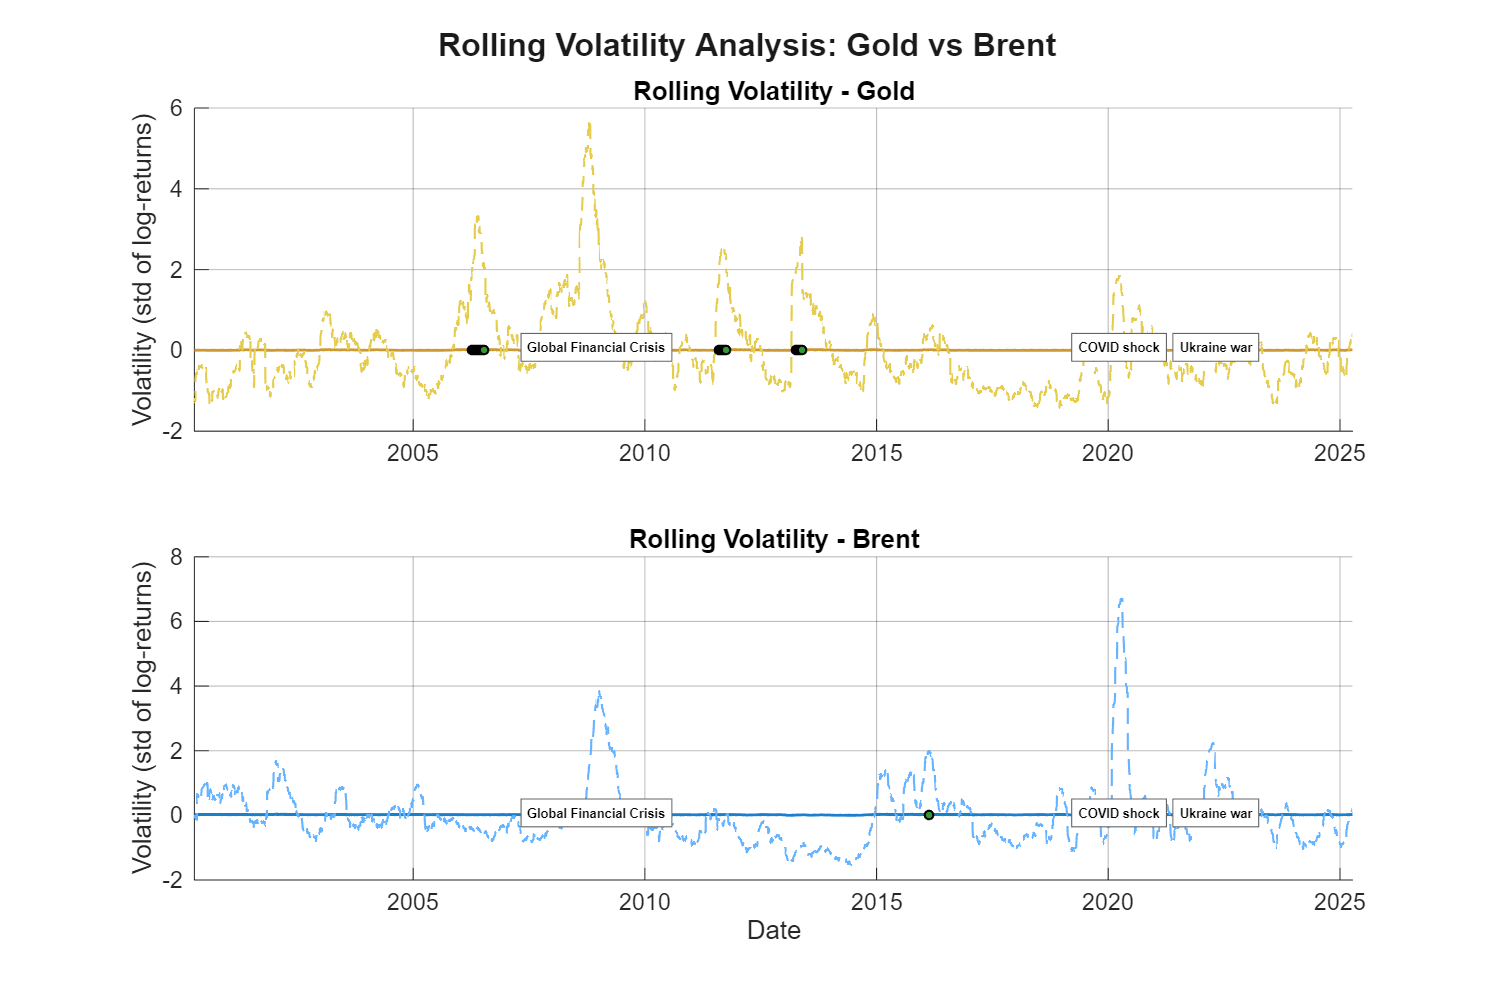


%% Allinea i due pannelli per confronto visivo
linkaxes([subplot(2,1,1), subplot(2,1,2)], 'x');

%% Titolo generale (opzionale)
sgtitle('Rolling Volatility Analysis: Gold vs Brent', ...
        'FontSize', font_size+4, 'FontWeight', 'bold', ...
        'Color', [0.1 0.1 0.1]);

%% Salvataggio alta qualità
saveas(gcf, 'volatility_spikes_two_assets.png');
print('volatility_spikes_high_quality', '-dpng', '-r300');  % Alta risoluzione


%% Tabella riepilogativa migliorata con info crisi
fprintf('\n=== SPIKE SUMMARY ===\n');


=== SPIKE SUMMARY ===


fprintf('Gold - Total spikes: %d\n', sum(spikes1));

Gold - Total spikes: 292


fprintf('Gold - Crisis spikes: %d\n', sum(is_crisis_spike1));

Gold - Crisis spikes: 127


fprintf('Gold - Normal spikes: %d\n', sum(~is_crisis_spike1));

Gold - Normal spikes: 165



fprintf('\nBrent - Total spikes: %d\n', sum(spikes2));


Brent - Total spikes: 237


fprintf('Brent - Crisis spikes: %d\n', sum(is_crisis_spike2));

Brent - Crisis spikes: 181


fprintf('Brent - Normal spikes: %d\n', sum(~is_crisis_spike2));

Brent - Normal spikes: 56



fprintf('\nFirst 5 Gold crisis spike dates:\n');


First 5 Gold crisis spike dates:


if any(is_crisis_spike1)
    disp(spike_dates1(find(is_crisis_spike1, 5)));
else
    disp('No crisis spikes found for Gold');
end

   01-Sep-2008
   02-Sep-2008
   03-Sep-2008
   04-Sep-2008
   05-Sep-2008




fprintf('\nFirst 5 Gold normal spike dates:\n');


First 5 Gold normal spike dates:


if any(~is_crisis_spike1)
    disp(spike_dates1(find(~is_crisis_spike1, 5)));
else
    disp('No normal spikes found for Gold');
end

   07-Apr-2006
   10-Apr-2006
   11-Apr-2006
   12-Apr-2006
   13-Apr-2006

